%prepare for Task3
ref_concatenated=[];
sur_concatenated=[];

for data_index = 1:20
    folderPath = sprintf('rawData\\data_%d\\', data_index);
    addpath(folderPath);
    
    filename = sprintf('data_%d.mat', data_index); 

    load(filename);

    %addpath('rawData\data_1\')
    %load('rawData\data_1\data_1.mat');

Task1

    %暂时先只处理0.01s
    seq_sur1=seq_sur(1:(length(seq_sur)/50));
    seq_ref1=seq_ref(1:(length(seq_sur)/50));
    duration1=0.01;

    %reference signal:freq-domain
    drawSpectrum(seq_ref1,f_s)
    drawDDCSpectrum(seq_ref1,f_s)
    AfterLPFSpectrum(seq_ref1,f_s);

    %reference signal:time-domain
    TimePlotting(seq_ref1,f_s,"Reference signal (raw)")
    DDC_TimePlotting(seq_ref1,f_s,"Reference signal (after DDC)")
    AfterLPF_TimePlotting(seq_ref1,f_s,"Reference signal (after LPF)", "Reference Signal",data_index)

    %surveillance signal:freq-domain
    drawSpectrum(seq_sur1,f_s)
    drawDDCSpectrum(seq_sur1,f_s)
    AfterLPFSpectrum(seq_sur1,f_s);

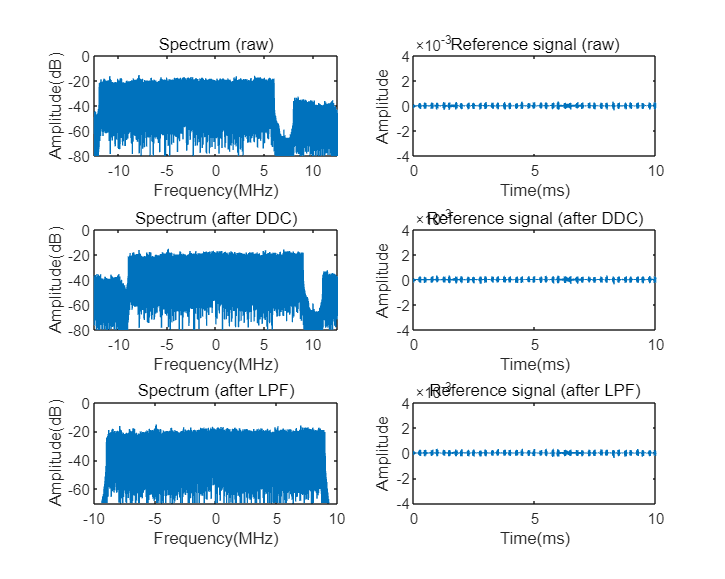

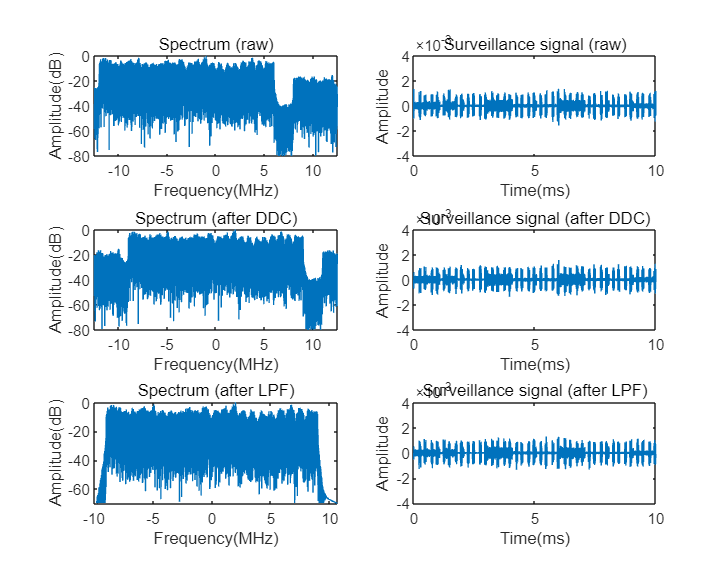

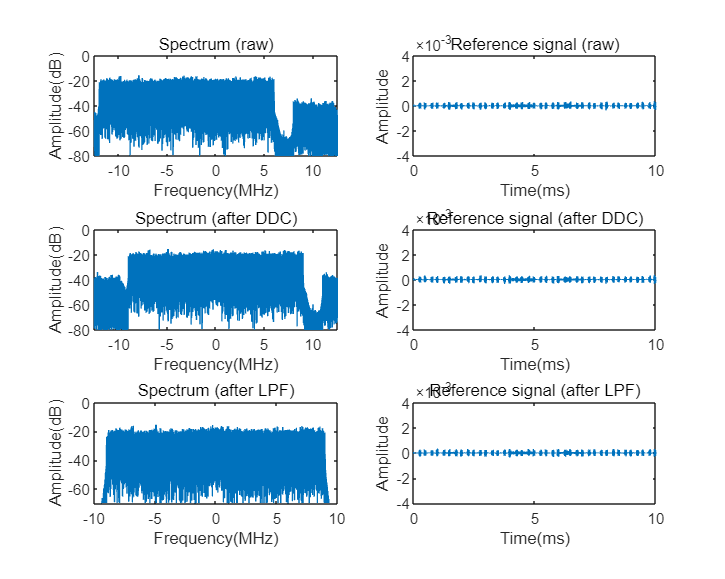

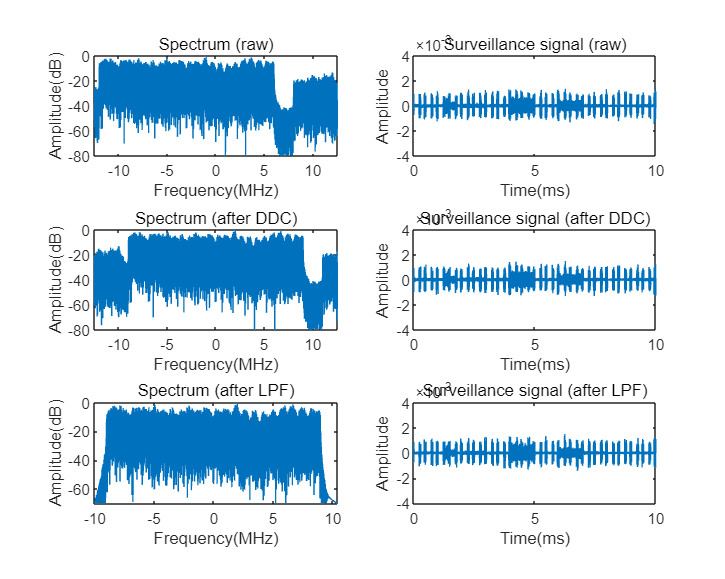

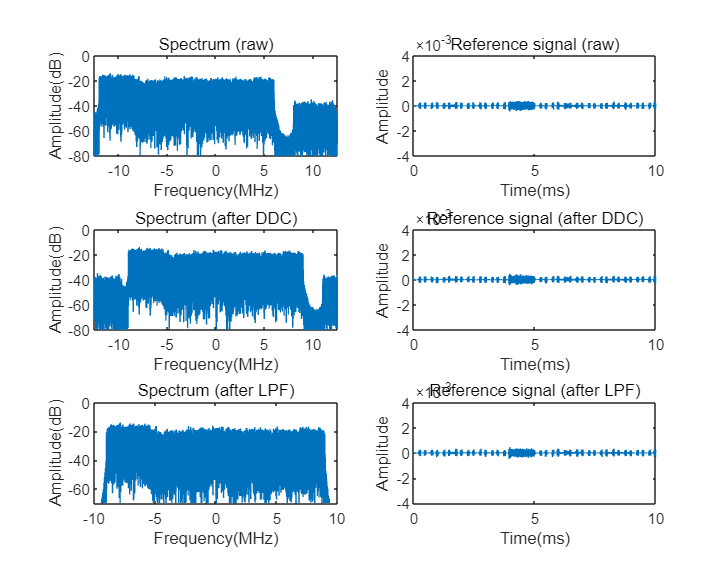

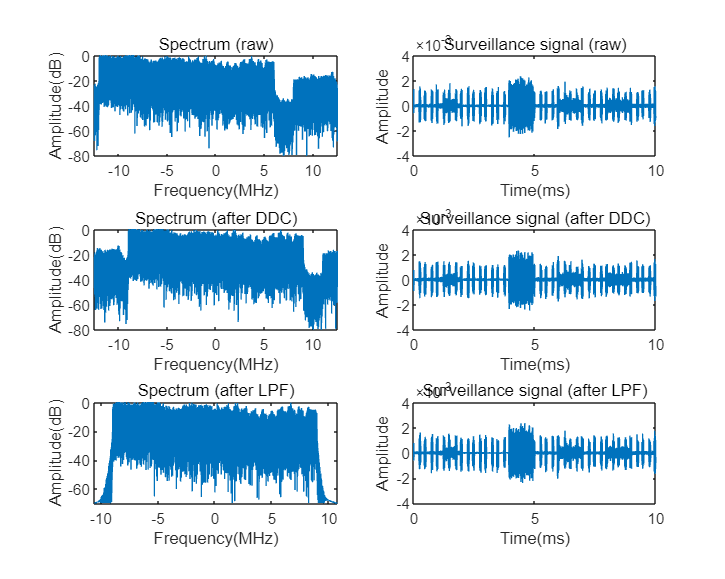

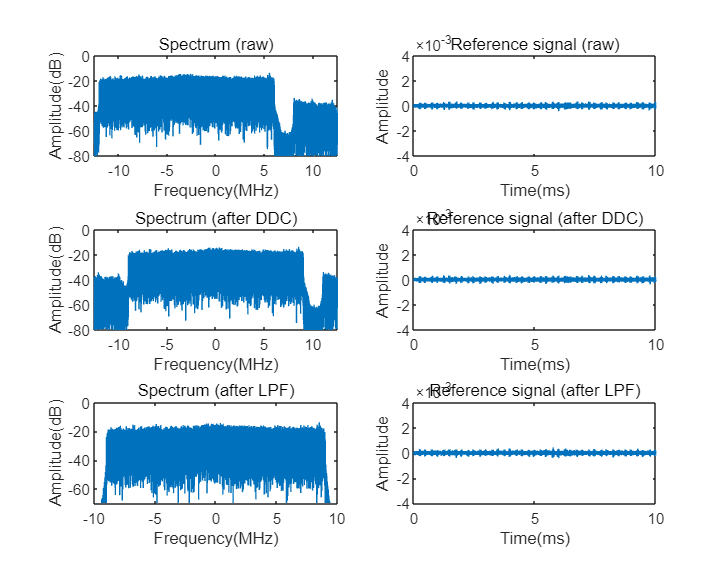

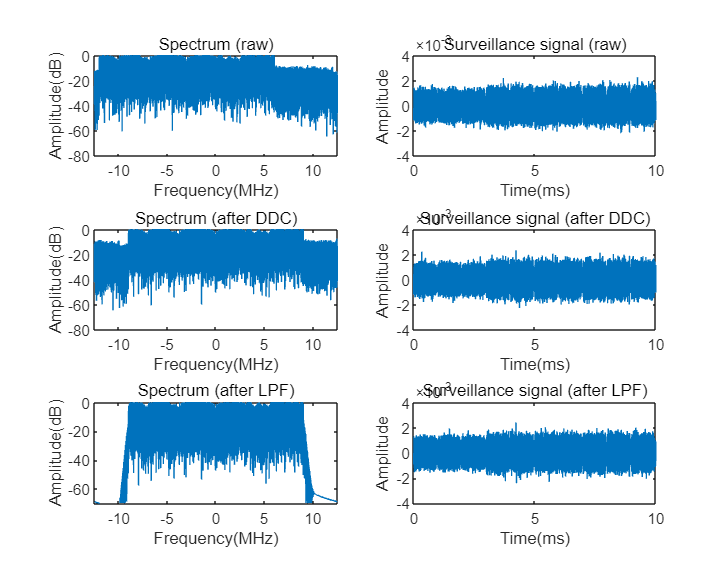

    %surveillance signal:time-domain
    TimePlotting(seq_sur1,f_s,"Surveillance signal (raw)")
    DDC_TimePlotting(seq_sur1,f_s,"Surveillance signal (after DDC)")
    AfterLPF_TimePlotting(seq_sur1,f_s,"Surveillance signal (after LPF)", "Surveillance Signal",data_index)

Task2

seq_ref1_after_LPF = 1.0e-03 *

  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0001i  -0.0000 + 0.0000i   0.0001 - 0.0001i   0.0000 - 0.0001i  -0.0001 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0001 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0001 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0001i   0.0007 - 0.0009i   0.0054 - 0.0056i   0.0197 - 0.0177i   0.0376 - 0.0264i   0.0287 - 0.0054i  -0.0218 + 0.0359i  -0.0534 + 0.0238i  -0.0123 - 0.0656i   0.0217 - 0.1204i  -0.0262 - 0.0745i  -0.0730 - 0.0124i  -0.0962 + 0.0424i  -0.1597 + 0.1144i  -0.1139 + 0.0956i   0.1028 - 0.0060i   0.1483 - 0.0070i  -0.0342 + 0.0382i  -0.0679 - 0.0120i   0.0185 - 0.0488i  -0.0158 - 0.0117i  -0.0532 + 0.0263i  -0.0466 + 0.0463i  -0.0581 + 0.0159i  -0.0139 - 0.0199i  -0.0084 - 0.0107i  -0.0682 - 0.0493i


seq_sur1_after_LPF =    0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0001 + 0.0001i  -0.0002 + 0.0000i  -0.0002 - 0.0002i   0.0001 - 0.0003i   0.0004 + 0.0001i   0.0003 + 0.0005i  -0.0001 + 0.0003i   0.0000 + 0.0000i   0.0003 + 0.0003i   0.0002 + 0.0003i  -0.0001 - 0.0002i  -0.0001 - 0.0003i  -0.0001 + 0.0000i   0.0000 - 0.0002i   0.0003 - 0.0003i   0.0002 - 0.0003i   0.0000 - 0.0009i  -0.0000 - 0.0007i   0.0002 + 0.0005i   0.0003 + 0.0001i   0.0002 - 0.0005i  -0.0000 + 0.0009i  -0.0002 + 0.0012i


matrix_normalized =     0.0012    0.0002    0.0003    0.0003    0.0001    0.0001    0.0001    0.0003    0.0001    0.0019    0.0006    0.0011    0.0000    0.0016    0.0003    0.0013    0.0003    0.0004    0.0004    0.0000    0.0000    0.0000    0.0996    0.0343    0.0161    0.0088    0.0036    0.0001    0.0002    0.0002    0.0002    0.0003    0.0021    0.0007    0.0005    0.0002    0.0005    0.0001    0.0004    0.0009    0.0001
    0.0001    0.0034    0.0020    0.0042    0.0008    0.0018    0.0004    0.0036    0.0017    0.0098    0.0050    0.0003    0.0010    0.0010    0.0022    0.0032    0.0161    0.0085    0.0220    0.0000    0.0000    0.0000    1.0000    0.5048    0.1758    0.0311    0.0320    0.0127    0.0007    0.0001    0.0034    0.0076    0.0042    0.0081    0.0019    0.0009    0.0000    0.0015    0.0021    0.0038    0.0009
    0.0005    0.0003    0.0000    0.0002    0.0006    0.0003    0.0003    0.0002    0.0013    0.0001    0.0001    0.0000    0.0003    0.0000    0.0001    0.00

cor_max_f_D = 4

cor_max_tau = 12

filename = 'Range-Doppler Spectrum data1.png'

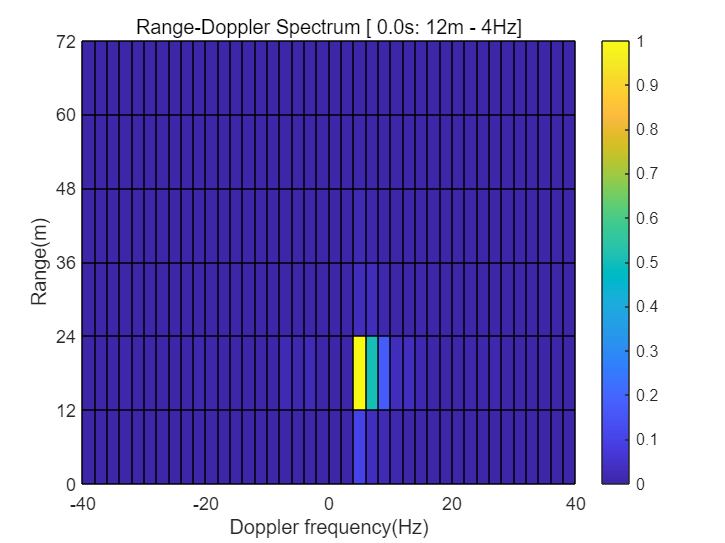

seq_ref1_after_LPF = 1.0e-03 *

   0.0001 - 0.0000i   0.0016 - 0.0003i   0.0077 - 0.0012i   0.0193 - 0.0013i   0.0227 + 0.0041i  -0.0008 + 0.0168i  -0.0323 + 0.0237i  -0.0217 + 0.0098i   0.0170 - 0.0085i   0.0118 - 0.0007i  -0.0178 + 0.0174i  -0.0017 + 0.0098i   0.0084 - 0.0041i  -0.0330 + 0.0084i  -0.0358 + 0.0162i   0.0026 - 0.0126i  -0.0012 - 0.0413i   0.0084 - 0.0218i   0.0451 + 0.0310i   0.0007 + 0.0435i  -0.0523 - 0.0133i   0.0023 - 0.0578i   0.0481 - 0.0307i   0.0078 + 0.0013i  -0.0221 - 0.0116i  -0.0027 - 0.0232i   0.0359 - 0.0136i   0.0670 - 0.0082i   0.0468 + 0.0059i  -0.0089 + 0.0302i  -0.0158 + 0.0083i   0.0239 - 0.0413i   0.0243 - 0.0205i  -0.0106 + 0.0375i  -0.0165 + 0.0189i  -0.0150 - 0.0278i  -0.0182 - 0.0008i   0.0125 + 0.0557i   0.0138 + 0.0651i  -0.0549 + 0.0401i  -0.0714 + 0.0121i  -0.0041 - 0.0176i   0.0186 - 0.0239i  -0.0317 + 0.0009i  -0.0610 - 0.0184i  -0.0278 - 0.0590i   0.0168 - 0.0115i   0.0185 + 0.0303i  -0.0021 - 0.0062i   0.0012 + 0.0045i


seq_sur1_after_LPF =   -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0001 + 0.0001i  -0.0001 + 0.0001i   0.0000 + 0.0000i   0.0001 - 0.0000i  -0.0003 + 0.0001i  -0.0006 + 0.0001i  -0.0003 - 0.0000i   0.0001 - 0.0002i   0.0001 - 0.0003i   0.0003 - 0.0006i   0.0007 - 0.0006i   0.0002 - 0.0001i  -0.0004 + 0.0002i   0.0001 + 0.0001i   0.0002 + 0.0000i  -0.0007 - 0.0003i  -0.0007 - 0.0005i   0.0003 - 0.0001i   0.0007 + 0.0000i   0.0003 - 0.0004i  -0.0001 - 0.0004i   0.0003 + 0.0001i   0.0005 + 0.0004i  -0.0003 + 0.0005i  -0.0008 + 0.0002i  -0.0004 - 0.0004i  -0.0004 - 0.0003i  -0.0002 + 0.0004i   0.0003 + 0.0004i   0.0000 - 0.0002i  -0.0001 - 0.0004i   0.0000 + 0.0002i  -0.0004 + 0.0004i  -0.0004 - 0.0002i   0.0001 - 0.0003i  -0.0002 + 0.0001i  -0.0003 - 0.0001i   0.0001 - 0.0006i   0.0003 - 0.0006i   0.0003 + 0.0000i   0.0003 + 0.0008i   0.0000 + 0.0005i  -0.0002 - 0.0002i  -0.0001 + 0.0000i  -0.0001 + 0.0001i  -0.0002 - 0.0005i   0.0002 - 0.0001i


matrix_normalized =     0.0012    0.0003    0.0003    0.0014    0.0001    0.0003    0.0008    0.0035    0.0008    0.0001    0.0032    0.0074    0.0136    0.0159    0.0244    0.0086    0.0561    0.0819    0.0286    0.0000    0.0000    0.0000    0.0389    0.0433    0.0008    0.0360    0.0648    0.0499    0.0034    0.0007    0.0035    0.0009    0.0001    0.0000    0.0042    0.0001    0.0000    0.0013    0.0004    0.0041    0.0015
    0.0033    0.0027    0.0000    0.0012    0.0000    0.0020    0.0160    0.0087    0.0005    0.0019    0.0195    0.0222    0.0230    0.0127    0.0238    0.0136    0.0425    0.1047    0.0560    0.0000    0.0000    0.0000    0.2018    0.2172    0.1264    0.1170    1.0000    0.2243    0.1832    0.0340    0.0207    0.0005    0.0000    0.0015    0.0032    0.0002    0.0005    0.0034    0.0001    0.0026    0.0030
    0.0009    0.0025    0.0001    0.0001    0.0000    0.0003    0.0038    0.0005    0.0000    0.0018    0.0031    0.0031    0.0030    0.0012    0.0027    0.00

cor_max_f_D = 12

cor_max_tau = 12

filename = 'Range-Doppler Spectrum data2.png'

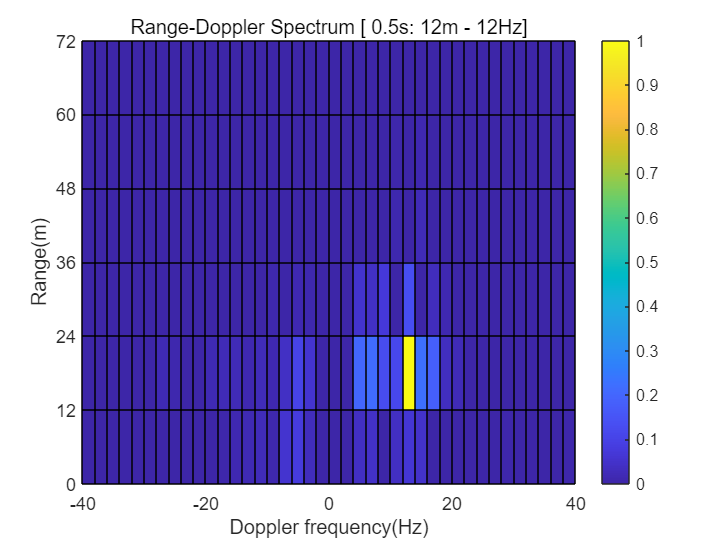

seq_ref1_after_LPF = 1.0e-03 *

   0.0000 + 0.0000i   0.0006 + 0.0005i   0.0029 + 0.0018i   0.0080 + 0.0026i   0.0114 - 0.0028i   0.0047 - 0.0170i  -0.0081 - 0.0286i  -0.0081 - 0.0242i   0.0022 - 0.0133i  -0.0042 - 0.0107i  -0.0126 - 0.0077i   0.0160 + 0.0012i   0.0386 - 0.0000i  -0.0017 - 0.0118i  -0.0321 - 0.0196i   0.0094 - 0.0160i   0.0420 + 0.0069i   0.0266 + 0.0306i   0.0109 + 0.0169i  -0.0157 - 0.0171i  -0.0308 - 0.0288i   0.0188 - 0.0112i   0.0417 + 0.0271i  -0.0082 + 0.0442i  -0.0162 + 0.0087i   0.0158 - 0.0175i   0.0254 - 0.0035i   0.0433 - 0.0001i   0.0241 + 0.0001i  -0.0320 + 0.0176i  -0.0086 + 0.0221i   0.0221 + 0.0199i  -0.0239 + 0.0232i  -0.0368 + 0.0054i  -0.0229 - 0.0282i  -0.0291 - 0.0285i  -0.0021 + 0.0298i  -0.0043 + 0.0658i  -0.0423 + 0.0006i  -0.0199 - 0.0565i  -0.0018 - 0.0251i  -0.0095 - 0.0094i   0.0065 - 0.0249i  -0.0168 - 0.0232i  -0.0245 - 0.0453i   0.0341 - 0.0420i   0.0332 + 0.0255i   0.0031 + 0.0312i   0.0103 - 0.0227i  -0.0066 - 0.0088i


seq_sur1_after_LPF =   -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0001 - 0.0000i  -0.0002 + 0.0000i  -0.0003 + 0.0002i  -0.0002 + 0.0004i   0.0001 + 0.0004i   0.0001 + 0.0000i  -0.0000 - 0.0002i   0.0000 + 0.0000i   0.0002 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0006i   0.0002 + 0.0009i   0.0001 + 0.0000i  -0.0003 - 0.0004i  -0.0003 + 0.0004i  -0.0000 + 0.0001i   0.0002 - 0.0011i   0.0004 - 0.0009i   0.0002 + 0.0003i   0.0000 + 0.0008i   0.0003 + 0.0005i   0.0006 - 0.0001i   0.0001 - 0.0003i  -0.0004 + 0.0001i  -0.0004 - 0.0001i   0.0000 - 0.0003i  -0.0001 + 0.0001i  -0.0004 + 0.0001i  -0.0003 - 0.0002i  -0.0000 + 0.0001i   0.0002 + 0.0002i   0.0003 - 0.0001i   0.0001 - 0.0002i   0.0001 + 0.0000i   0.0008 + 0.0002i   0.0005 - 0.0001i  -0.0004 - 0.0003i  -0.0002 - 0.0001i   0.0001 + 0.0001i  -0.0001 + 0.0003i  -0.0003 + 0.0004i  -0.0005 + 0.0002i  -0.0004 - 0.0003i   0.0004 - 0.0002i   0.0003 + 0.0000i  -0.0001 + 0.0001i   0.0004 + 0.0000i   0.0003 + 0.0002i


matrix_normalized =     0.0004    0.0025    0.0022    0.0071    0.0048    0.0000    0.0084    0.0008    0.0023    0.0002    0.0161    0.0000    0.0121    0.0057    0.1602    0.0208    0.0101    0.0070    0.0087    0.0000    0.0000    0.0000    0.0047    0.0367    0.0145    0.0003    0.0035    0.0006    0.0057    0.0144    0.0057    0.0004    0.0085    0.0006    0.0094    0.0135    0.0032    0.0012    0.0123    0.0016    0.0000
    0.0056    0.0022    0.0311    0.0085    0.0062    0.0073    0.0371    0.0055    0.0308    0.0078    0.0358    0.0096    0.0970    0.0714    1.0000    0.1080    0.1041    0.1926    0.0019    0.0000    0.0000    0.0000    0.0005    0.2217    0.0630    0.0074    0.3852    0.0002    0.0049    0.1461    0.0037    0.0043    0.1643    0.0312    0.2989    0.0176    0.0147    0.0444    0.0452    0.0035    0.0070
    0.0000    0.0005    0.0066    0.0002    0.0002    0.0060    0.0001    0.0008    0.0022    0.0015    0.0001    0.0046    0.0096    0.0091    0.0305    0.00

cor_max_f_D = -12

cor_max_tau = 12

filename = 'Range-Doppler Spectrum data3.png'

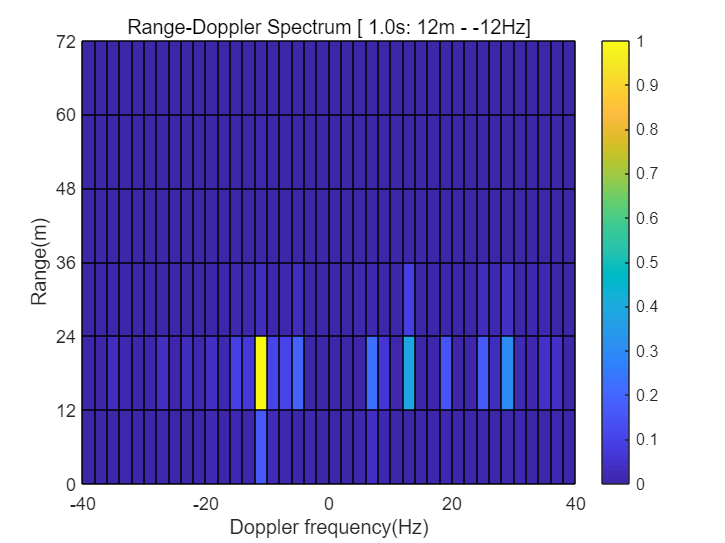

seq_ref1_after_LPF = 1.0e-03 *

  -0.0001 - 0.0002i  -0.0010 - 0.0025i  -0.0044 - 0.0120i  -0.0088 - 0.0303i  -0.0036 - 0.0402i   0.0204 - 0.0199i   0.0450 + 0.0072i   0.0405 - 0.0047i   0.0225 - 0.0247i   0.0301 + 0.0078i   0.0440 + 0.0444i   0.0237 + 0.0329i  -0.0007 + 0.0308i   0.0155 + 0.0330i   0.0458 - 0.0087i   0.0383 - 0.0078i   0.0028 + 0.0477i   0.0047 + 0.0439i   0.0367 + 0.0254i   0.0128 + 0.0405i  -0.0409 + 0.0127i  -0.0505 - 0.0083i  -0.0564 + 0.0107i  -0.0402 - 0.0042i   0.0320 - 0.0001i   0.0412 + 0.0335i   0.0085 + 0.0216i   0.0528 + 0.0056i   0.0768 - 0.0176i   0.0538 - 0.0370i   0.0472 + 0.0189i  -0.0237 + 0.0304i  -0.0649 - 0.0259i   0.0241 - 0.0210i   0.0301 - 0.0410i  -0.0504 - 0.0672i  -0.0292 + 0.0150i   0.0223 + 0.0432i   0.0377 + 0.0077i   0.0245 + 0.0398i  -0.0307 + 0.0254i  -0.0209 - 0.0243i   0.0212 + 0.0007i  -0.0272 + 0.0089i  -0.0437 - 0.0132i   0.0113 + 0.0005i   0.0227 + 0.0468i   0.0117 + 0.0857i   0.0009 + 0.0323i  -0.0204 - 0.0242i


seq_sur1_after_LPF =   -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0001 + 0.0000i  -0.0002 + 0.0000i  -0.0005 + 0.0000i  -0.0007 - 0.0000i  -0.0005 - 0.0001i   0.0001 + 0.0000i   0.0002 + 0.0003i  -0.0002 + 0.0003i  -0.0006 - 0.0000i  -0.0006 - 0.0003i  -0.0008 - 0.0003i  -0.0008 - 0.0004i   0.0000 - 0.0003i   0.0004 - 0.0000i  -0.0000 - 0.0001i   0.0001 - 0.0001i   0.0006 + 0.0005i   0.0003 + 0.0006i  -0.0002 + 0.0002i  -0.0003 + 0.0002i  -0.0003 + 0.0006i  -0.0001 + 0.0004i   0.0002 - 0.0001i  -0.0002 - 0.0004i   0.0000 + 0.0000i   0.0003 + 0.0006i  -0.0004 + 0.0002i  -0.0004 - 0.0005i   0.0004 - 0.0003i   0.0002 + 0.0002i  -0.0005 + 0.0004i  -0.0003 + 0.0002i   0.0000 - 0.0002i   0.0000 + 0.0001i  -0.0001 + 0.0006i  -0.0001 + 0.0004i   0.0002 - 0.0001i   0.0004 - 0.0003i  -0.0000 - 0.0003i  -0.0002 - 0.0003i   0.0001 - 0.0004i   0.0005 - 0.0005i   0.0006 + 0.0000i   0.0004 + 0.0005i   0.0002 + 0.0003i  -0.0001 - 0.0001i  -0.0003 + 0.0000i  -0.0002 - 0.0003i


matrix_normalized =     0.0003    0.0001    0.0000    0.0001    0.0007    0.0006    0.0018    0.0026    0.0018    0.0017    0.0007    0.0013    0.0075    0.0158    0.0169    0.0079    0.0005    0.0002    0.0016    0.0000    0.0000    0.0000    0.0004    0.0006    0.0017    0.0074    0.0108    0.0039    0.0001    0.0034    0.0001    0.1211    0.0219    0.0000    0.0000    0.0006    0.0012    0.0016    0.0014    0.0004    0.0002
    0.0002    0.0001    0.0005    0.0041    0.0063    0.0073    0.0066    0.0063    0.0077    0.0111    0.0132    0.0119    0.0245    0.0804    0.0988    0.0674    0.0324    0.0163    0.0358    0.0000    0.0000    0.0000    0.0361    0.0248    0.0318    0.0615    0.0930    0.0850    0.0126    0.0282    0.0009    1.0000    0.3139    0.0123    0.0084    0.0074    0.0064    0.0025    0.0015    0.0000    0.0000
    0.0000    0.0000    0.0001    0.0008    0.0008    0.0004    0.0000    0.0000    0.0003    0.0011    0.0026    0.0024    0.0003    0.0024    0.0060    0.00

cor_max_f_D = 22

cor_max_tau = 12

filename = 'Range-Doppler Spectrum data4.png'

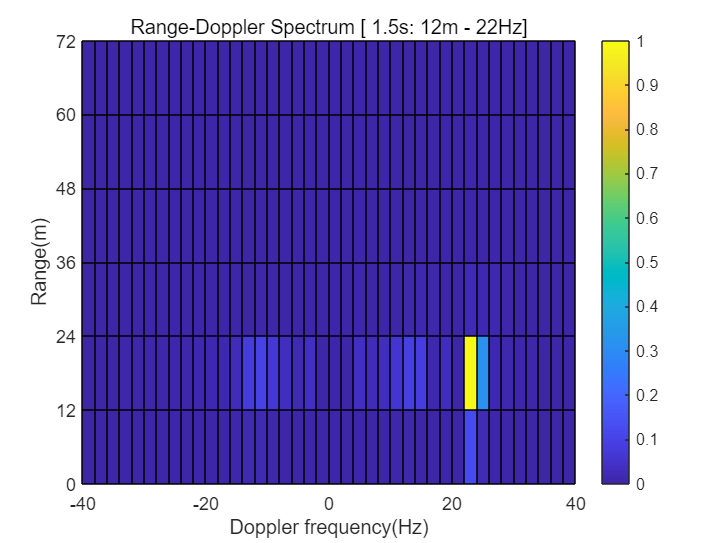

seq_ref1_after_LPF = 1.0e-03 *

  -0.0000 - 0.0001i  -0.0003 - 0.0007i  -0.0021 - 0.0039i  -0.0079 - 0.0095i  -0.0193 - 0.0049i  -0.0318 + 0.0321i  -0.0359 + 0.0866i  -0.0279 + 0.0871i  -0.0157 + 0.0203i  -0.0098 + 0.0017i  -0.0127 + 0.0683i  -0.0196 + 0.0634i  -0.0211 - 0.0464i  -0.0133 - 0.0724i  -0.0087 + 0.0011i  -0.0195 + 0.0122i  -0.0153 - 0.0297i   0.0398 - 0.0434i   0.0708 - 0.0194i  -0.0283 + 0.0385i  -0.1490 + 0.0016i  -0.1124 - 0.1582i  -0.0103 - 0.1481i   0.0096 + 0.0433i   0.0294 + 0.0692i   0.0773 - 0.0356i   0.0499 - 0.0361i  -0.0065 + 0.0064i  -0.0125 + 0.0097i  -0.0053 + 0.0001i   0.0245 + 0.0101i   0.0889 + 0.0651i   0.1049 + 0.0636i   0.0395 - 0.0269i  -0.0435 - 0.0666i  -0.0860 - 0.0874i  -0.0816 - 0.1225i  -0.0484 - 0.0171i  -0.0136 + 0.1282i  -0.0080 + 0.0781i   0.0021 - 0.0560i   0.0473 - 0.0817i   0.0443 - 0.0305i  -0.0222 + 0.0021i  -0.0547 - 0.0303i  -0.0370 - 0.0786i   0.0100 - 0.0351i   0.0450 + 0.0443i   0.0413 + 0.0179i   0.0687 - 0.0424i


seq_sur1_after_LPF =   -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0001 - 0.0001i  -0.0001 - 0.0003i   0.0000 - 0.0004i   0.0001 - 0.0002i   0.0000 + 0.0003i  -0.0002 + 0.0005i  -0.0002 + 0.0001i  -0.0001 - 0.0004i   0.0000 - 0.0006i   0.0004 - 0.0007i   0.0003 - 0.0006i  -0.0003 + 0.0001i  -0.0004 + 0.0005i   0.0002 + 0.0001i  -0.0001 - 0.0002i  -0.0009 - 0.0002i  -0.0006 - 0.0001i   0.0002 + 0.0002i   0.0005 + 0.0001i   0.0004 - 0.0005i   0.0001 - 0.0003i   0.0002 + 0.0003i   0.0006 - 0.0000i   0.0002 - 0.0003i  -0.0003 + 0.0003i  -0.0002 + 0.0003i  -0.0001 - 0.0002i  -0.0002 + 0.0000i  -0.0001 + 0.0003i  -0.0003 + 0.0000i  -0.0004 - 0.0002i  -0.0002 - 0.0000i  -0.0001 + 0.0002i  -0.0003 + 0.0000i  -0.0005 - 0.0004i  -0.0003 - 0.0003i   0.0002 + 0.0003i   0.0000 + 0.0004i  -0.0002 + 0.0001i   0.0004 + 0.0001i   0.0008 + 0.0004i   0.0001 + 0.0000i  -0.0008 - 0.0005i  -0.0002 - 0.0002i   0.0004 - 0.0001i  -0.0003 - 0.0007i  -0.0002 - 0.0005i


matrix_normalized =     0.0139    0.0099    0.0053    0.0012    0.0004    0.0398    0.0131    0.0037    0.0025    0.0007    0.0437    0.0054    0.0921    0.0206    0.0017    0.0120    0.0944    0.0080    0.0361    0.0000    0.0001    0.0000    0.0631    0.0000    0.0603    0.0351    0.0004    0.0251    0.1402    0.0069    0.0081    0.4824    0.1347    0.0577    0.0041    0.0594    0.0006    0.0123    0.0014    0.0195    0.0004
    0.0022    0.0166    0.0023    0.0006    0.0054    0.0410    0.0134    0.0112    0.0040    0.0023    0.0177    0.0026    0.0937    0.0229    0.0050    0.0140    0.1275    0.0052    0.0242    0.0000    0.0001    0.0000    0.0638    0.0155    0.0552    0.0361    0.0016    0.0387    0.1771    0.0469    0.0060    0.6175    1.0000    0.0199    0.0066    0.0707    0.0004    0.0142    0.0109    0.0623    0.0063
    0.0006    0.0020    0.0001    0.0004    0.0087    0.0157    0.0050    0.0038    0.0035    0.0015    0.0068    0.0015    0.0168    0.0104    0.0007    0.00

cor_max_f_D = 24

cor_max_tau = 12

filename = 'Range-Doppler Spectrum data5.png'

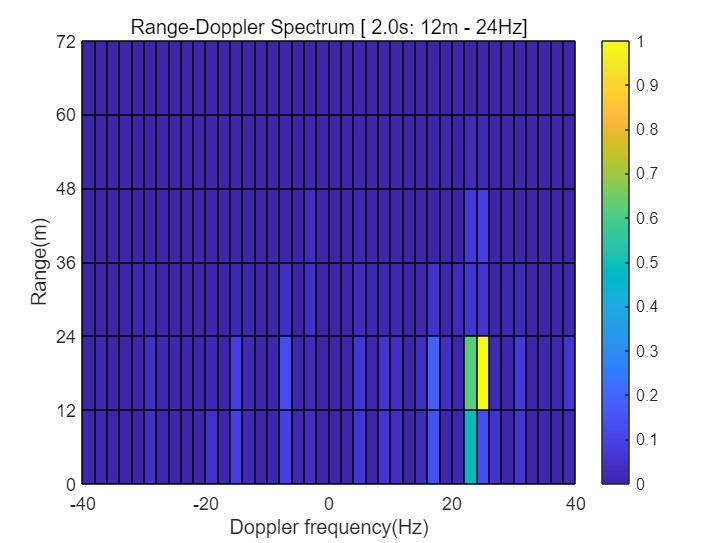

seq_ref1_after_LPF = 1.0e-03 *

   0.0001 - 0.0000i   0.0015 - 0.0002i   0.0069 - 0.0014i   0.0171 - 0.0048i   0.0204 - 0.0105i   0.0007 - 0.0156i  -0.0289 - 0.0186i  -0.0294 - 0.0215i  -0.0042 - 0.0192i   0.0004 - 0.0026i  -0.0099 + 0.0111i   0.0065 - 0.0032i   0.0206 - 0.0163i  -0.0076 + 0.0054i  -0.0341 + 0.0163i  -0.0178 - 0.0102i   0.0200 - 0.0136i   0.0432 + 0.0143i   0.0181 + 0.0208i  -0.0328 + 0.0079i  -0.0324 - 0.0187i   0.0094 - 0.0437i   0.0259 - 0.0054i   0.0209 + 0.0423i   0.0003 + 0.0110i  -0.0245 - 0.0138i   0.0132 + 0.0084i   0.0657 - 0.0022i   0.0227 - 0.0060i  -0.0273 + 0.0301i   0.0122 + 0.0249i   0.0359 - 0.0079i   0.0003 - 0.0067i  -0.0253 + 0.0022i  -0.0444 - 0.0101i  -0.0339 - 0.0179i   0.0272 + 0.0250i   0.0296 + 0.0712i  -0.0316 + 0.0233i  -0.0412 - 0.0428i  -0.0200 - 0.0268i  -0.0061 - 0.0057i   0.0123 - 0.0141i  -0.0170 - 0.0204i  -0.0420 - 0.0516i   0.0182 - 0.0573i   0.0431 + 0.0069i  -0.0086 + 0.0318i  -0.0157 - 0.0150i   0.0069 - 0.0334i


seq_sur1_after_LPF =   -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0001 + 0.0000i  -0.0002 + 0.0001i  -0.0002 + 0.0003i   0.0001 + 0.0005i   0.0003 + 0.0004i   0.0002 - 0.0000i  -0.0001 - 0.0002i   0.0000 + 0.0001i   0.0002 + 0.0003i   0.0002 + 0.0003i   0.0003 + 0.0006i   0.0004 + 0.0005i  -0.0001 - 0.0003i  -0.0004 - 0.0005i  -0.0001 + 0.0001i  -0.0000 - 0.0002i  -0.0001 - 0.0010i   0.0000 - 0.0004i   0.0001 + 0.0004i   0.0003 + 0.0005i   0.0006 + 0.0005i   0.0003 + 0.0002i  -0.0004 - 0.0003i  -0.0006 + 0.0002i  -0.0001 + 0.0002i   0.0000 - 0.0004i  -0.0003 - 0.0001i  -0.0003 + 0.0003i   0.0000 - 0.0001i   0.0000 - 0.0002i   0.0002 - 0.0000i   0.0005 - 0.0002i   0.0001 - 0.0001i   0.0000 + 0.0001i   0.0006 - 0.0004i   0.0004 - 0.0006i  -0.0004 - 0.0002i  -0.0003 + 0.0000i   0.0000 + 0.0001i   0.0000 + 0.0002i  -0.0001 + 0.0004i  -0.0003 + 0.0003i  -0.0001 - 0.0003i   0.0005 - 0.0004i   0.0004 + 0.0003i   0.0001 + 0.0004i   0.0003 - 0.0002i   0.0001 + 0.0002i


matrix_normalized =     0.0007    0.0000    0.0001    0.0013    0.0000    0.0061    0.0021    0.0061    0.0058    0.0003    0.0024    0.0006    0.0001    0.0086    0.1018    0.0007    0.0088    0.0188    0.2244    0.0000    0.0000    0.0000    0.0729    0.0085    0.0336    0.0078    0.0103    0.0020    0.0055    0.0034    0.0219    0.0561    0.5846    0.0076    0.0004    0.0069    0.0060    0.0020    0.0000    0.0001    0.0001
    0.0009    0.0005    0.0001    0.0048    0.0008    0.0112    0.0008    0.0110    0.0149    0.0013    0.0193    0.0059    0.0003    0.0033    0.0626    0.0139    0.0795    0.0096    0.0881    0.0000    0.0000    0.0000    0.1710    0.0353    0.0591    0.0029    0.1450    0.0256    0.0034    0.0066    0.0661    0.0171    1.0000    0.0009    0.0069    0.0396    0.0031    0.0013    0.0022    0.0008    0.0010
    0.0003    0.0007    0.0000    0.0005    0.0005    0.0004    0.0004    0.0003    0.0035    0.0008    0.0010    0.0005    0.0001    0.0000    0.0001    0.01

cor_max_f_D = 24

cor_max_tau = 12

filename = 'Range-Doppler Spectrum data6.png'

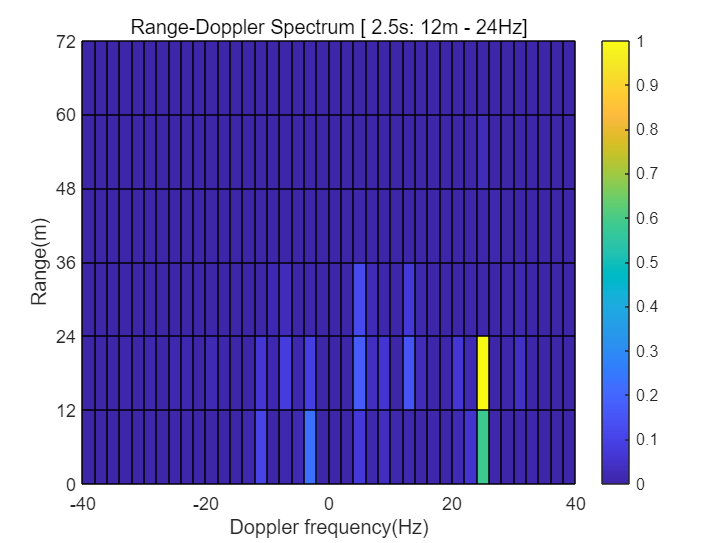

seq_ref1_after_LPF = 1.0e-03 *

   0.0000 - 0.0001i   0.0003 - 0.0012i   0.0018 - 0.0057i   0.0068 - 0.0154i   0.0146 - 0.0244i   0.0172 - 0.0245i   0.0073 - 0.0214i  -0.0045 - 0.0255i  -0.0055 - 0.0226i  -0.0046 - 0.0048i   0.0029 - 0.0019i   0.0396 - 0.0054i   0.0566 + 0.0257i  -0.0037 + 0.0312i  -0.0429 - 0.0339i   0.0176 - 0.0329i   0.0495 + 0.0638i   0.0143 + 0.0620i   0.0300 - 0.0241i   0.0381 - 0.0144i  -0.0201 + 0.0193i  -0.0124 - 0.0071i   0.0138 + 0.0171i  -0.0549 + 0.0541i  -0.0677 + 0.0025i  -0.0054 - 0.0352i  -0.0297 - 0.0150i  -0.0504 - 0.0306i   0.0116 - 0.0587i   0.0142 - 0.0249i  -0.0342 + 0.0329i  -0.0169 + 0.0416i   0.0223 + 0.0160i   0.0060 + 0.0044i  -0.0186 - 0.0168i   0.0144 - 0.0124i   0.0306 + 0.0803i  -0.0231 + 0.0994i  -0.0190 - 0.0311i   0.0363 - 0.0711i   0.0035 + 0.0021i  -0.0282 - 0.0086i   0.0055 - 0.0405i  -0.0103 - 0.0103i  -0.0194 - 0.0084i   0.0397 - 0.0143i   0.0391 + 0.0320i  -0.0147 + 0.0466i  -0.0042 - 0.0246i   0.0334 - 0.0557i


seq_sur1_after_LPF =   -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0001 + 0.0000i  -0.0002 + 0.0001i  -0.0003 + 0.0003i  -0.0003 + 0.0004i  -0.0000 + 0.0004i   0.0002 + 0.0002i   0.0002 + 0.0002i  -0.0000 + 0.0003i  -0.0003 + 0.0001i  -0.0008 - 0.0001i  -0.0012 + 0.0000i  -0.0006 + 0.0000i   0.0005 - 0.0002i   0.0006 - 0.0003i  -0.0001 - 0.0001i   0.0002 - 0.0002i   0.0005 - 0.0000i  -0.0002 + 0.0002i  -0.0005 + 0.0000i  -0.0002 - 0.0001i  -0.0003 + 0.0003i  -0.0003 + 0.0002i   0.0002 - 0.0005i   0.0003 - 0.0007i   0.0003 - 0.0001i   0.0007 + 0.0006i   0.0003 + 0.0004i  -0.0002 - 0.0000i   0.0002 - 0.0001i   0.0002 + 0.0002i  -0.0002 + 0.0006i   0.0001 + 0.0006i   0.0000 - 0.0001i  -0.0003 - 0.0002i  -0.0000 + 0.0003i  -0.0001 - 0.0000i  -0.0004 - 0.0007i   0.0002 - 0.0004i   0.0004 - 0.0000i  -0.0002 - 0.0003i  -0.0001 - 0.0004i   0.0005 - 0.0002i   0.0008 + 0.0000i   0.0006 + 0.0004i   0.0000 + 0.0005i  -0.0003 + 0.0003i  -0.0001 + 0.0002i   0.0001 - 0.0001i


matrix_normalized =     0.0000    0.0000    0.0011    0.0000    0.0003    0.0018    0.0000    0.0013    0.0012    0.0001    0.0021    0.0109    0.0130    0.0003    0.0107    0.0635    0.0195    0.0009    0.0011    0.0000    0.0000    0.0000    0.0009    0.0068    0.0104    0.0260    0.0290    0.0004    0.0067    0.0330    0.0035    1.0000    0.0174    0.1373    0.0160    0.0050    0.0247    0.0027    0.0053    0.0057    0.0003
    0.0002    0.0018    0.0070    0.0006    0.0005    0.0016    0.0002    0.0011    0.0008    0.0014    0.0199    0.0964    0.0801    0.0009    0.1174    0.5388    0.3714    0.0460    0.0192    0.0000    0.0000    0.0000    0.0072    0.0653    0.2599    0.4487    0.0963    0.0003    0.0468    0.0008    0.0228    0.1149    0.0076    0.0511    0.0098    0.0062    0.0037    0.0078    0.0186    0.0169    0.0018
    0.0001    0.0006    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0002    0.0014    0.0053    0.0018    0.0000    0.0058    0.02

cor_max_f_D = 22

cor_max_tau = 0

filename = 'Range-Doppler Spectrum data7.png'

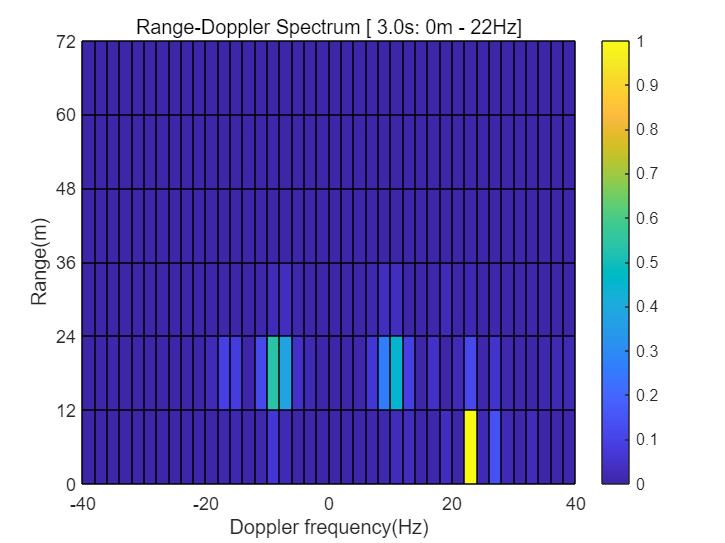

seq_ref1_after_LPF = 1.0e-03 *

  -0.0001 + 0.0001i  -0.0007 + 0.0011i  -0.0033 + 0.0046i  -0.0076 + 0.0105i  -0.0036 + 0.0144i   0.0233 + 0.0164i   0.0593 + 0.0246i   0.0581 + 0.0319i   0.0221 + 0.0247i   0.0267 + 0.0358i   0.0687 + 0.0801i   0.0325 + 0.0653i  -0.0690 - 0.0214i  -0.0804 - 0.0202i  -0.0088 + 0.0616i   0.0058 + 0.0479i  -0.0369 - 0.0154i  -0.0492 - 0.0259i  -0.0020 - 0.0312i   0.0315 + 0.0248i  -0.0801 + 0.1076i  -0.2184 + 0.0184i  -0.1140 - 0.0811i   0.0714 - 0.0001i   0.0592 + 0.0091i   0.0166 - 0.0978i   0.0447 - 0.0799i   0.0028 - 0.0023i  -0.0293 + 0.0088i   0.0072 + 0.0015i   0.0265 - 0.0062i   0.0711 - 0.0108i   0.0799 - 0.0325i  -0.0270 - 0.0567i  -0.0825 - 0.0090i  -0.0800 + 0.0215i  -0.1203 - 0.0139i  -0.0595 + 0.0208i   0.0839 + 0.0791i   0.0865 + 0.0406i  -0.0036 - 0.0237i  -0.0291 - 0.0531i  -0.0005 - 0.0484i   0.0118 - 0.0110i  -0.0396 + 0.0186i  -0.0991 + 0.0103i  -0.0566 - 0.0266i   0.0268 - 0.0323i   0.0369 - 0.0188i   0.0163 - 0.0701i


seq_sur1_after_LPF =   -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0001 - 0.0000i  -0.0002 - 0.0001i  -0.0004 - 0.0001i  -0.0003 + 0.0000i  -0.0002 + 0.0002i  -0.0002 + 0.0003i  -0.0002 + 0.0001i   0.0000 - 0.0002i  -0.0004 - 0.0004i  -0.0010 - 0.0009i  -0.0002 - 0.0011i   0.0009 - 0.0004i   0.0003 + 0.0004i  -0.0003 + 0.0001i   0.0002 - 0.0002i  -0.0003 + 0.0002i  -0.0010 + 0.0002i  -0.0003 - 0.0003i   0.0004 - 0.0006i   0.0002 - 0.0009i   0.0006 - 0.0009i   0.0003 - 0.0001i  -0.0001 + 0.0005i   0.0005 + 0.0002i   0.0004 - 0.0000i  -0.0002 + 0.0001i   0.0004 + 0.0001i   0.0007 + 0.0002i   0.0000 + 0.0004i  -0.0003 + 0.0006i  -0.0005 + 0.0007i  -0.0002 + 0.0003i   0.0002 - 0.0003i   0.0001 - 0.0001i   0.0000 + 0.0002i  -0.0000 - 0.0000i  -0.0002 + 0.0000i   0.0003 + 0.0003i   0.0007 + 0.0003i   0.0004 + 0.0003i   0.0006 + 0.0004i   0.0006 - 0.0000i  -0.0004 - 0.0002i  -0.0007 - 0.0001i   0.0001 - 0.0004i   0.0001 - 0.0004i  -0.0005 - 0.0003i  -0.0001 - 0.0005i


matrix_normalized =     0.0002    0.0001    0.0005    0.0002    0.0000    0.0001    0.0007    0.0004    0.0001    0.0010    0.0038    0.0114    0.0155    0.0198    0.0105    0.0002    0.0018    0.0099    0.0771    0.0000    0.0000    0.0000    0.3147    0.0008    0.0075    0.0018    0.0893    0.0706    0.0000    0.2268    0.1017    0.0030    0.0342    0.0097    0.0000    0.0002    0.0014    0.0036    0.0001    0.0004    0.0029
    0.0023    0.0017    0.0058    0.0003    0.0021    0.0017    0.0101    0.0000    0.0017    0.0195    0.0196    0.1329    0.1715    0.1530    0.0747    0.0001    0.0173    0.0477    0.9922    0.0000    0.0000    0.0000    1.0000    0.0316    0.0443    0.0034    0.2139    0.1850    0.0028    0.4625    0.0111    0.0358    0.0364    0.0120    0.0018    0.0025    0.0046    0.0009    0.0053    0.0023    0.0134
    0.0000    0.0001    0.0006    0.0001    0.0003    0.0007    0.0008    0.0001    0.0003    0.0021    0.0003    0.0124    0.0108    0.0070    0.0035    0.00

cor_max_f_D = 4

cor_max_tau = 12

filename = 'Range-Doppler Spectrum data8.png'

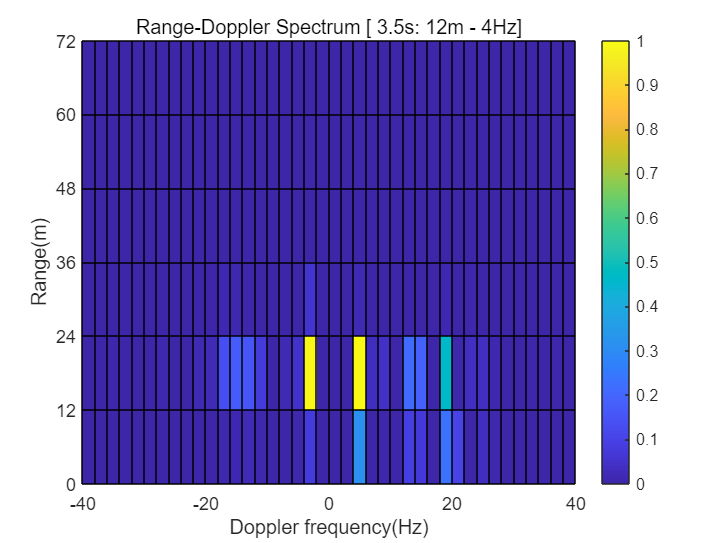

seq_ref1_after_LPF = 1.0e-03 *

   0.0001 - 0.0001i   0.0007 - 0.0006i   0.0037 - 0.0032i   0.0095 - 0.0085i   0.0125 - 0.0110i   0.0025 - 0.0030i  -0.0164 + 0.0058i  -0.0209 - 0.0047i  -0.0033 - 0.0170i   0.0129 + 0.0038i   0.0109 + 0.0166i   0.0023 - 0.0271i   0.0003 - 0.0442i   0.0011 + 0.0208i  -0.0102 + 0.0467i  -0.0258 - 0.0048i  -0.0103 - 0.0184i   0.0164 - 0.0039i   0.0007 - 0.0052i  -0.0261 + 0.0267i  -0.0294 + 0.0175i  -0.0331 - 0.0684i  -0.0055 - 0.0605i   0.0433 + 0.0206i   0.0180 + 0.0157i  -0.0242 - 0.0089i   0.0088 - 0.0150i   0.0308 - 0.0469i   0.0111 - 0.0103i   0.0137 + 0.0532i   0.0107 + 0.0042i  -0.0047 - 0.0439i   0.0041 - 0.0023i  -0.0033 + 0.0256i  -0.0358 + 0.0260i  -0.0255 + 0.0265i   0.0320 + 0.0074i   0.0530 + 0.0062i   0.0062 + 0.0313i  -0.0258 + 0.0345i  -0.0106 + 0.0139i  -0.0039 - 0.0089i  -0.0061 - 0.0074i  -0.0263 + 0.0180i  -0.0731 + 0.0118i  -0.0484 - 0.0219i   0.0256 - 0.0222i   0.0115 + 0.0010i  -0.0197 + 0.0078i   0.0149 - 0.0127i


seq_sur1_after_LPF =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0001i   0.0001 + 0.0001i   0.0003 + 0.0002i   0.0005 + 0.0002i   0.0004 - 0.0000i   0.0001 - 0.0001i  -0.0002 - 0.0001i  -0.0000 - 0.0001i   0.0005 + 0.0000i   0.0010 + 0.0003i   0.0010 + 0.0006i  -0.0000 + 0.0003i  -0.0008 - 0.0001i  -0.0005 - 0.0000i  -0.0001 + 0.0001i  -0.0005 - 0.0004i  -0.0004 - 0.0008i   0.0001 - 0.0001i   0.0001 + 0.0003i   0.0002 - 0.0001i   0.0004 - 0.0001i  -0.0001 + 0.0001i  -0.0007 + 0.0000i  -0.0005 + 0.0003i  -0.0001 + 0.0004i  -0.0001 - 0.0001i  -0.0003 + 0.0004i  -0.0002 + 0.0008i   0.0001 - 0.0000i   0.0002 - 0.0004i   0.0001 - 0.0004i   0.0002 - 0.0006i   0.0003 - 0.0002i   0.0003 - 0.0001i   0.0002 - 0.0008i   0.0001 - 0.0005i  -0.0000 + 0.0003i  -0.0001 + 0.0003i  -0.0000 + 0.0004i   0.0001 + 0.0003i   0.0000 + 0.0000i  -0.0003 - 0.0000i  -0.0002 - 0.0007i   0.0002 - 0.0009i   0.0006 + 0.0001i   0.0007 - 0.0001i   0.0004 - 0.0005i   0.0002 + 0.0005i


matrix_normalized =     0.0026    0.0008    0.0016    0.0022    0.0016    0.0085    0.0020    0.0167    0.0011    0.0347    0.0044    0.0385    0.0031    0.0277    0.0029    0.0112    0.0042    0.0062    0.0057    0.0000    0.0000    0.0000    0.0113    0.5003    1.0000    0.0775    0.1567    0.2289    0.0766    0.0039    0.0355    0.0003    0.0302    0.0003    0.0130    0.0001    0.0224    0.0046    0.0054    0.0027    0.0020
    0.0050    0.0005    0.0053    0.0022    0.0019    0.0233    0.0004    0.0443    0.0109    0.0679    0.0305    0.0481    0.0472    0.0452    0.0843    0.0187    0.1260    0.0110    0.1849    0.0000    0.0000    0.0000    0.1794    0.1265    0.8674    0.0003    0.0385    0.0042    0.0419    0.0379    0.0271    0.0098    0.0376    0.0098    0.0041    0.0066    0.0149    0.0115    0.0032    0.0061    0.0039
    0.0008    0.0009    0.0018    0.0009    0.0003    0.0006    0.0005    0.0006    0.0011    0.0008    0.0015    0.0003    0.0017    0.0006    0.0030    0.00

cor_max_f_D = 8

cor_max_tau = 0

filename = 'Range-Doppler Spectrum data9.png'

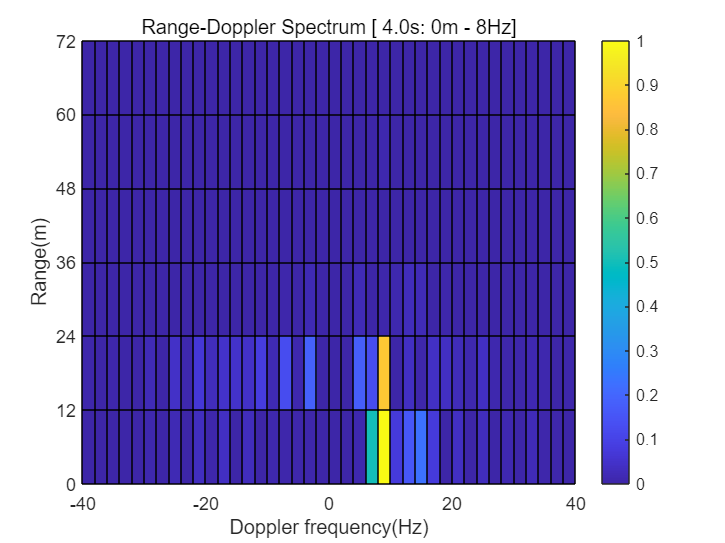

seq_ref1_after_LPF = 1.0e-03 *

   0.0000 - 0.0000i   0.0002 - 0.0002i   0.0010 - 0.0014i   0.0022 - 0.0047i   0.0016 - 0.0090i  -0.0032 - 0.0080i  -0.0113 + 0.0000i  -0.0200 + 0.0025i  -0.0268 - 0.0071i  -0.0220 - 0.0129i   0.0039 - 0.0158i   0.0298 - 0.0341i   0.0245 - 0.0342i  -0.0023 + 0.0106i  -0.0238 + 0.0223i  -0.0278 - 0.0234i   0.0034 - 0.0237i   0.0420 + 0.0057i   0.0150 - 0.0201i  -0.0382 - 0.0201i  -0.0181 + 0.0259i   0.0264 + 0.0019i   0.0191 - 0.0229i   0.0056 + 0.0282i  -0.0028 + 0.0251i  -0.0286 - 0.0265i  -0.0209 - 0.0193i   0.0035 - 0.0159i  -0.0241 - 0.0267i  -0.0360 + 0.0072i   0.0242 + 0.0198i   0.0607 + 0.0051i   0.0355 + 0.0232i   0.0121 + 0.0226i  -0.0062 - 0.0101i  -0.0124 - 0.0028i   0.0298 + 0.0418i   0.0441 + 0.0495i  -0.0168 - 0.0076i  -0.0311 - 0.0460i   0.0123 - 0.0142i  -0.0141 + 0.0076i  -0.0540 + 0.0004i  -0.0166 - 0.0017i   0.0053 - 0.0260i   0.0018 - 0.0241i   0.0326 + 0.0172i   0.0128 - 0.0069i  -0.0371 - 0.0387i   0.0076 + 0.0044i


seq_sur1_after_LPF =   -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0001 + 0.0001i  -0.0002 + 0.0002i  -0.0001 + 0.0002i   0.0000 + 0.0001i   0.0001 + 0.0002i   0.0000 + 0.0005i  -0.0000 + 0.0004i  -0.0001 + 0.0001i  -0.0005 + 0.0001i  -0.0007 + 0.0003i   0.0000 + 0.0001i   0.0005 - 0.0003i   0.0001 - 0.0001i  -0.0001 - 0.0001i   0.0007 - 0.0004i   0.0007 - 0.0004i  -0.0006 + 0.0000i  -0.0007 + 0.0002i   0.0001 + 0.0004i   0.0000 + 0.0005i   0.0001 - 0.0002i   0.0004 - 0.0007i  -0.0001 - 0.0005i  -0.0004 - 0.0001i   0.0002 + 0.0001i   0.0000 + 0.0001i  -0.0004 + 0.0000i   0.0002 + 0.0000i   0.0004 + 0.0003i   0.0002 + 0.0004i   0.0003 + 0.0002i  -0.0001 + 0.0002i  -0.0002 + 0.0004i   0.0006 - 0.0000i   0.0005 - 0.0004i  -0.0002 - 0.0000i  -0.0003 - 0.0001i  -0.0003 - 0.0005i  -0.0005 - 0.0001i  -0.0001 + 0.0001i   0.0002 - 0.0002i   0.0006 - 0.0000i   0.0007 + 0.0003i  -0.0001 + 0.0002i  -0.0002 + 0.0005i   0.0004 + 0.0007i  -0.0000 + 0.0002i


matrix_normalized =     0.0000    0.0003    0.0000    0.0001    0.0000    0.0002    0.0001    0.0004    0.0004    0.0001    0.0001    0.0002    0.0016    0.0038    0.0068    0.0253    0.0632    0.2888    1.0000    0.0000    0.0000    0.0000    0.3812    0.0909    0.0193    0.0022    0.0021    0.0007    0.0007    0.0005    0.0006    0.0002    0.0004    0.0000    0.0000    0.0000    0.0001    0.0003    0.0002    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0000    0.0001    0.0007    0.0001    0.0048    0.0106    0.0391    0.1052    0.0000    0.0000    0.0000    0.0430    0.0077    0.0030    0.0011    0.0026    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0001    0.0001    0.0000    0.0000    0.0001    0.0002    0.0002    0.0002
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.00

cor_max_f_D = -4

cor_max_tau = 0

filename = 'Range-Doppler Spectrum data10.png'

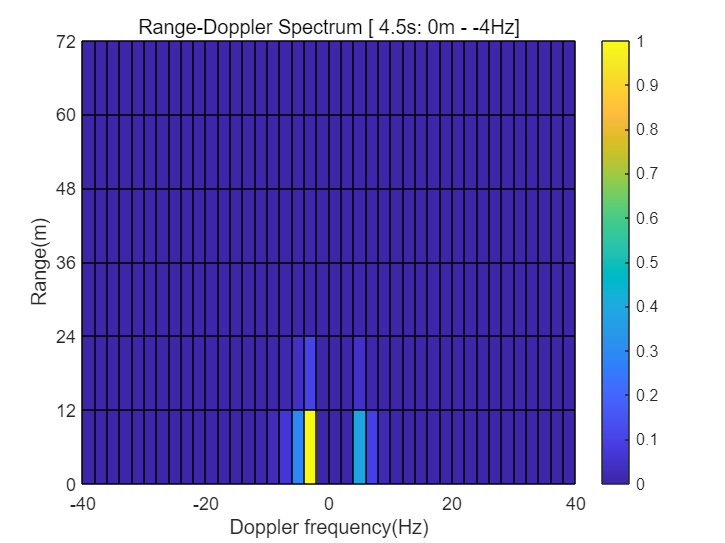

seq_ref1_after_LPF = 1.0e-03 *

  -0.0000 - 0.0001i  -0.0003 - 0.0017i  -0.0007 - 0.0089i   0.0038 - 0.0244i   0.0255 - 0.0321i   0.0643 + 0.0013i   0.0766 + 0.0615i   0.0155 + 0.0612i  -0.0610 - 0.0139i  -0.0397 - 0.0270i   0.0395 + 0.0551i   0.0414 + 0.0574i   0.0014 - 0.0339i   0.0164 - 0.0364i   0.0287 + 0.0160i   0.0258 + 0.0181i   0.0603 + 0.0563i   0.0318 + 0.0698i  -0.0311 - 0.0366i   0.0647 - 0.0475i   0.1428 + 0.0440i  -0.0101 + 0.0044i  -0.0909 - 0.0296i   0.0523 + 0.0173i   0.1061 - 0.0398i   0.0163 - 0.0404i  -0.0084 + 0.0493i   0.0037 - 0.0800i  -0.0476 - 0.2140i  -0.0807 - 0.0779i  -0.0228 + 0.0256i   0.0148 + 0.0306i  -0.0248 + 0.1054i   0.0017 + 0.1087i   0.0807 + 0.0482i   0.0697 + 0.0516i   0.0372 + 0.0096i   0.0236 - 0.0601i   0.0023 - 0.0561i   0.0553 - 0.0369i   0.0545 + 0.0067i  -0.1110 + 0.0499i  -0.1671 - 0.0091i  -0.0437 - 0.0460i   0.0129 + 0.0501i  -0.0405 + 0.1161i  -0.1100 + 0.0596i  -0.1051 + 0.0013i  -0.0054 + 0.0073i   0.0491 + 0.0354i


seq_sur1_after_LPF =   -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0001 + 0.0000i  -0.0002 + 0.0001i  -0.0004 + 0.0002i  -0.0002 + 0.0003i   0.0003 + 0.0000i   0.0005 - 0.0002i   0.0001 - 0.0001i  -0.0002 + 0.0001i  -0.0000 - 0.0006i  -0.0004 - 0.0013i  -0.0009 - 0.0005i  -0.0003 + 0.0009i   0.0002 + 0.0009i  -0.0001 + 0.0001i  -0.0002 - 0.0001i   0.0000 + 0.0004i  -0.0001 + 0.0006i  -0.0001 - 0.0003i  -0.0004 - 0.0014i  -0.0009 - 0.0007i  -0.0002 + 0.0004i   0.0008 + 0.0002i   0.0003 - 0.0004i   0.0001 - 0.0006i   0.0007 - 0.0005i   0.0002 + 0.0006i   0.0000 + 0.0011i   0.0008 - 0.0001i   0.0003 - 0.0006i  -0.0008 + 0.0001i  -0.0006 + 0.0003i  -0.0001 + 0.0002i  -0.0002 - 0.0002i  -0.0002 - 0.0003i  -0.0005 + 0.0003i  -0.0007 + 0.0006i  -0.0002 + 0.0001i   0.0008 - 0.0001i   0.0010 - 0.0001i   0.0006 + 0.0004i   0.0002 + 0.0006i  -0.0000 + 0.0002i   0.0001 + 0.0001i   0.0004 + 0.0004i   0.0000 + 0.0003i  -0.0003 + 0.0004i  -0.0000 - 0.0002i   0.0003 - 0.0009i


matrix_normalized =     0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0000    0.0000    0.0001    0.0000    0.0013    0.0007    0.0058    0.0598    1.0000    0.7547    0.3583    0.0731    0.0128    0.0000    0.0000    0.0000    0.0003    0.0001    0.0004    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0001    0.0001    0.0000    0.0000    0.0002    0.0020    0.0022    0.0911    0.1342    0.0299    0.0145    0.0002    0.0000    0.0000    0.0000    0.0004    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0002    0.0046    0.00

cor_max_f_D = -12

cor_max_tau = 0

filename = 'Range-Doppler Spectrum data11.png'

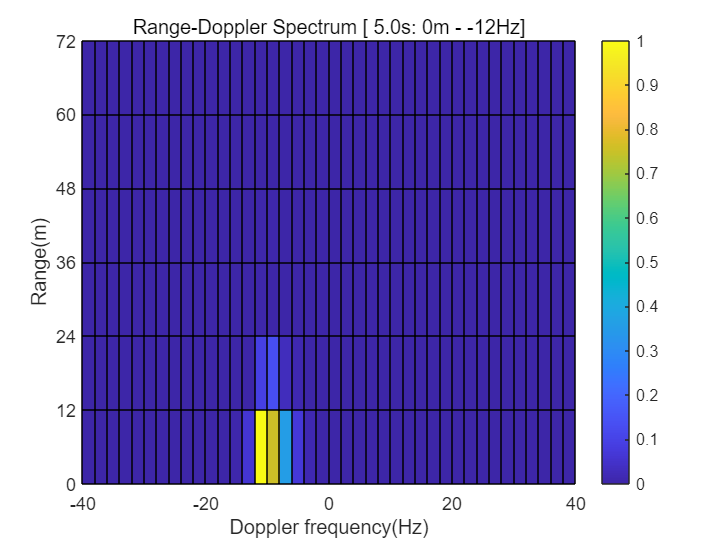

seq_ref1_after_LPF = 1.0e-03 *

  -0.0002 - 0.0000i  -0.0025 - 0.0004i  -0.0135 - 0.0018i  -0.0389 - 0.0031i  -0.0621 + 0.0062i  -0.0423 + 0.0411i   0.0193 + 0.0862i   0.0401 + 0.0881i  -0.0171 + 0.0464i  -0.0546 + 0.0475i  -0.0207 + 0.0840i  -0.0050 + 0.0173i  -0.0217 - 0.1103i   0.0017 - 0.0850i   0.0194 + 0.0373i  -0.0115 + 0.0388i  -0.0170 - 0.0330i   0.0033 - 0.0661i   0.0031 - 0.0649i  -0.0205 + 0.0108i  -0.1066 + 0.0520i  -0.1724 - 0.0714i  -0.0657 - 0.0961i   0.0699 + 0.0660i   0.0655 + 0.0653i   0.0367 - 0.0609i   0.0261 - 0.0419i  -0.0218 + 0.0008i  -0.0313 - 0.0111i   0.0106 + 0.0019i   0.0514 - 0.0152i   0.0949 - 0.0293i   0.0812 - 0.0176i   0.0021 - 0.0517i  -0.0472 - 0.0325i  -0.0733 + 0.0094i  -0.0739 - 0.0670i  -0.0008 - 0.0685i   0.0436 + 0.0675i   0.0006 + 0.0829i  -0.0247 - 0.0047i  -0.0117 - 0.0393i   0.0063 - 0.0355i   0.0202 + 0.0062i  -0.0336 + 0.0299i  -0.0892 - 0.0425i  -0.0151 - 0.0840i   0.0567 - 0.0130i   0.0417 + 0.0169i   0.0656 - 0.0501i


seq_sur1_after_LPF =    0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0001i  -0.0001 - 0.0003i  -0.0003 - 0.0005i  -0.0002 - 0.0005i  -0.0000 + 0.0001i  -0.0001 + 0.0004i  -0.0001 - 0.0003i   0.0004 - 0.0007i   0.0005 + 0.0004i  -0.0001 + 0.0011i  -0.0003 + 0.0004i  -0.0000 + 0.0002i  -0.0005 + 0.0005i  -0.0009 - 0.0001i   0.0001 - 0.0005i   0.0013 + 0.0001i   0.0010 - 0.0000i   0.0003 - 0.0002i   0.0004 + 0.0003i   0.0003 - 0.0001i  -0.0006 - 0.0005i  -0.0010 - 0.0001i  -0.0001 - 0.0002i   0.0005 - 0.0000i   0.0002 + 0.0011i  -0.0000 + 0.0008i  -0.0001 - 0.0003i  -0.0007 - 0.0003i  -0.0013 - 0.0001i  -0.0009 + 0.0001i   0.0002 + 0.0007i   0.0005 + 0.0008i  -0.0001 + 0.0005i  -0.0002 + 0.0001i   0.0003 - 0.0003i   0.0003 + 0.0002i  -0.0002 + 0.0010i  -0.0004 + 0.0008i   0.0000 - 0.0001i   0.0005 - 0.0007i   0.0002 - 0.0007i  -0.0000 + 0.0000i   0.0005 + 0.0004i   0.0006 - 0.0002i  -0.0000 - 0.0001i  -0.0002 + 0.0005i


matrix_normalized =     0.0002    0.0002    0.0000    0.0004    0.0002    0.0017    0.0013    0.0002    0.0009    0.0021    0.0014    0.0197    0.3551    1.0000    0.0478    0.0061    0.0072    0.0016    0.0009    0.0000    0.0000    0.0000    0.0001    0.0002    0.0000    0.0003    0.0001    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0001    0.0001    0.0007    0.0000    0.0000
    0.0000    0.0001    0.0000    0.0000    0.0001    0.0002    0.0003    0.0003    0.0000    0.0004    0.0007    0.0034    0.0592    0.1856    0.0075    0.0009    0.0006    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0023    0.0025    0.0000    0.00

cor_max_f_D = -14

cor_max_tau = 0

filename = 'Range-Doppler Spectrum data12.png'

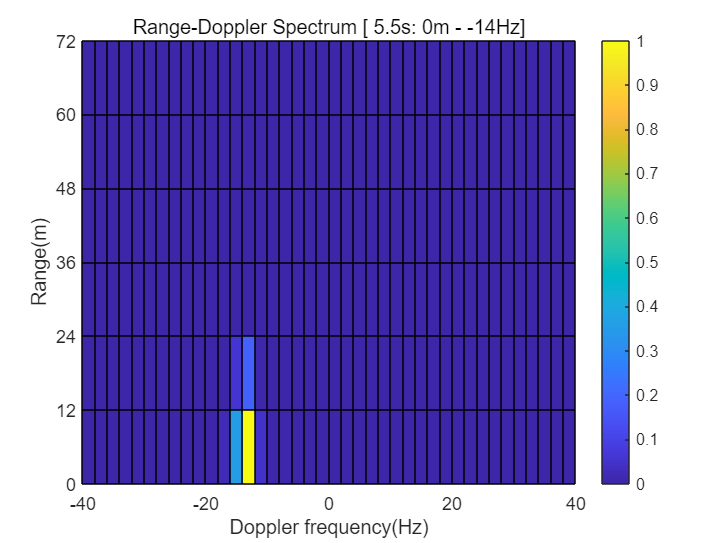

seq_ref1_after_LPF = 1.0e-03 *

  -0.0000 - 0.0002i  -0.0007 - 0.0025i  -0.0043 - 0.0127i  -0.0166 - 0.0353i  -0.0420 - 0.0548i  -0.0728 - 0.0380i  -0.0868 + 0.0114i  -0.0733 + 0.0316i  -0.0571 - 0.0004i  -0.0692 - 0.0261i  -0.0790 - 0.0328i  -0.0154 - 0.0684i   0.0938 - 0.0857i   0.1094 - 0.0186i   0.0098 + 0.0434i  -0.0317 + 0.0234i   0.0593 - 0.0035i   0.1229 - 0.0094i   0.0516 - 0.0425i  -0.0407 - 0.0768i  -0.0131 - 0.0937i   0.0824 - 0.1116i   0.0616 - 0.0772i  -0.0668 + 0.0136i  -0.0797 + 0.0655i   0.0098 + 0.0604i  -0.0154 + 0.0206i  -0.0855 - 0.0461i  -0.0256 - 0.0598i   0.0650 - 0.0094i   0.0670 + 0.0354i   0.0256 + 0.0943i   0.0078 + 0.1095i   0.0270 + 0.0164i   0.0254 - 0.0220i   0.0342 + 0.0064i   0.1406 - 0.0403i   0.1452 - 0.0507i  -0.0603 - 0.0025i  -0.1218 - 0.0229i   0.0259 - 0.0127i   0.0473 + 0.0277i  -0.0116 - 0.0005i   0.0049 + 0.0050i  -0.0085 + 0.0034i   0.0076 - 0.0583i   0.0850 - 0.0287i   0.0447 + 0.0234i  -0.0093 + 0.0346i   0.0573 + 0.0883i


seq_sur1_after_LPF =   -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0001i  -0.0001 - 0.0002i  -0.0002 - 0.0005i  -0.0002 - 0.0007i  -0.0002 - 0.0006i  -0.0002 - 0.0002i  -0.0001 - 0.0000i   0.0000 - 0.0002i   0.0000 - 0.0003i  -0.0002 + 0.0000i  -0.0001 + 0.0002i   0.0004 - 0.0003i   0.0005 - 0.0005i  -0.0002 + 0.0002i  -0.0004 + 0.0002i   0.0003 - 0.0004i   0.0002 - 0.0001i  -0.0006 + 0.0006i   0.0002 + 0.0002i   0.0013 - 0.0001i   0.0005 + 0.0001i  -0.0004 - 0.0001i  -0.0002 - 0.0002i  -0.0002 + 0.0001i  -0.0002 + 0.0001i   0.0004 + 0.0001i   0.0004 + 0.0000i   0.0001 - 0.0001i   0.0003 + 0.0003i  -0.0000 + 0.0004i  -0.0004 + 0.0002i  -0.0002 + 0.0004i  -0.0001 + 0.0005i   0.0001 + 0.0002i   0.0007 + 0.0005i   0.0006 + 0.0004i  -0.0002 - 0.0002i  -0.0006 - 0.0002i  -0.0004 + 0.0001i  -0.0002 + 0.0002i  -0.0005 + 0.0002i  -0.0002 - 0.0001i   0.0006 - 0.0001i   0.0002 - 0.0002i   0.0001 - 0.0001i   0.0006 + 0.0006i  -0.0000 + 0.0006i  -0.0004 - 0.0001i


matrix_normalized =     0.0000    0.0001    0.0000    0.0000    0.0000    0.0002    0.0005    0.0009    0.0031    0.0269    0.0139    0.0190    1.0000    0.0066    0.0379    0.0011    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000
    0.0000    0.0002    0.0000    0.0001    0.0000    0.0000    0.0003    0.0006    0.0013    0.0169    0.0070    0.0048    0.6140    0.0012    0.0252    0.0001    0.0001    0.0000    0.0000         0    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0002    0.0014    0.0001    0.0001    0.00

cor_max_f_D = -16

cor_max_tau = 0

filename = 'Range-Doppler Spectrum data13.png'

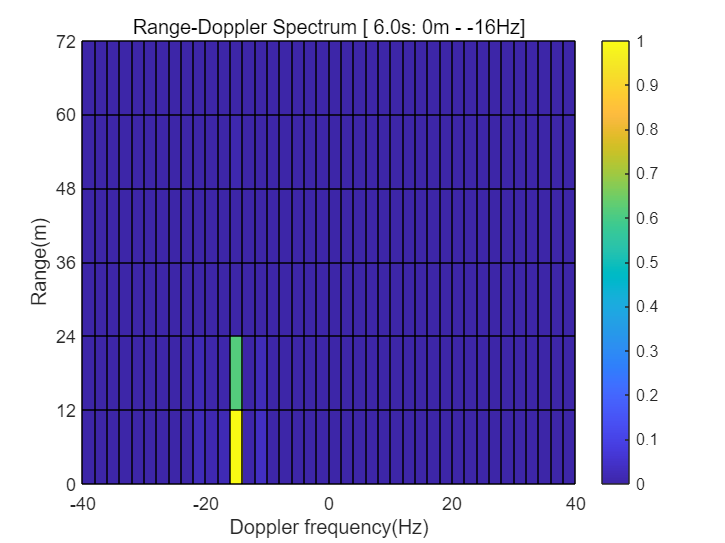

seq_ref1_after_LPF = 1.0e-03 *

  -0.0001 - 0.0001i  -0.0013 - 0.0016i  -0.0065 - 0.0077i  -0.0166 - 0.0208i  -0.0154 - 0.0323i   0.0229 - 0.0264i   0.0734 - 0.0097i   0.0471 - 0.0096i  -0.0536 - 0.0189i  -0.0628 - 0.0017i   0.0623 + 0.0208i   0.1057 + 0.0001i   0.0032 - 0.0306i  -0.0340 - 0.0219i   0.0326 - 0.0106i   0.0774 - 0.0194i   0.1097 - 0.0015i   0.0908 + 0.0353i  -0.0071 + 0.0190i   0.0046 - 0.0479i   0.0763 - 0.0663i  -0.0124 + 0.0139i  -0.0666 + 0.0787i   0.0292 + 0.0054i   0.0234 - 0.0916i  -0.0131 - 0.0509i   0.0470 - 0.0010i  -0.0253 - 0.0765i  -0.1530 - 0.0980i  -0.0633 + 0.0041i   0.0625 + 0.0282i   0.0363 - 0.0025i   0.0225 + 0.0534i   0.0914 + 0.0655i   0.0998 - 0.0270i   0.0246 - 0.0562i  -0.0179 + 0.0020i  -0.0417 + 0.0212i  -0.0824 - 0.0401i  -0.0349 - 0.0728i   0.0389 + 0.0152i  -0.0176 + 0.0898i  -0.0944 + 0.0543i  -0.0761 + 0.0272i  -0.0072 + 0.0358i   0.0614 + 0.0664i   0.0515 + 0.1264i   0.0022 + 0.0829i   0.0197 - 0.0271i   0.0370 - 0.0207i


seq_sur1_after_LPF =   -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0001i   0.0000 + 0.0002i   0.0001 + 0.0004i   0.0002 + 0.0004i   0.0003 + 0.0001i   0.0001 - 0.0003i  -0.0001 - 0.0003i  -0.0000 - 0.0001i   0.0001 - 0.0002i  -0.0001 - 0.0005i   0.0001 - 0.0002i   0.0008 + 0.0005i   0.0006 + 0.0005i  -0.0001 - 0.0001i  -0.0000 + 0.0000i   0.0002 + 0.0002i  -0.0001 - 0.0003i  -0.0000 - 0.0007i   0.0002 - 0.0003i  -0.0003 + 0.0001i  -0.0001 + 0.0002i   0.0007 + 0.0003i   0.0005 + 0.0001i   0.0000 - 0.0003i   0.0001 - 0.0004i   0.0003 - 0.0000i   0.0004 + 0.0000i  -0.0001 - 0.0001i  -0.0007 + 0.0001i  -0.0007 + 0.0004i  -0.0005 + 0.0003i   0.0001 + 0.0003i   0.0004 + 0.0002i  -0.0004 - 0.0003i  -0.0004 - 0.0003i   0.0002 + 0.0001i  -0.0004 + 0.0001i  -0.0004 - 0.0002i   0.0004 - 0.0003i   0.0004 - 0.0000i   0.0003 + 0.0005i   0.0002 + 0.0006i  -0.0003 + 0.0002i   0.0001 - 0.0001i   0.0005 - 0.0001i   0.0003 + 0.0002i   0.0003 - 0.0001i   0.0002 - 0.0006i


matrix_normalized =     0.0020    0.0010    0.0000    0.0002    0.0016    0.0000    0.0086    0.0025    0.0056    0.3234    1.0000    0.1936    0.6132    0.0820    0.0002    0.0003    0.0011    0.0023    0.0001    0.0000    0.0000         0    0.0000    0.0000    0.0001    0.0003    0.0000    0.0000    0.0002    0.0000    0.0002    0.0003    0.0001    0.0002    0.0002    0.0000    0.0001    0.0003    0.0000    0.0002    0.0001
    0.0029    0.0029    0.0001    0.0001    0.0002    0.0029    0.0046    0.0093    0.0004    0.2247    0.8887    0.2724    0.6719    0.1004    0.0040    0.0007    0.0021    0.0015    0.0039    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0006    0.0005    0.0002    0.0007    0.0008    0.0007    0.0015    0.0009    0.0006    0.0013    0.0007    0.0002    0.0001    0.0000    0.0002    0.0003
    0.0001    0.0001    0.0003    0.0001    0.0003    0.0005    0.0004    0.0003    0.0001    0.0008    0.0012    0.0017    0.0003    0.0003    0.0001    0.00

cor_max_f_D = -20

cor_max_tau = 0

filename = 'Range-Doppler Spectrum data14.png'

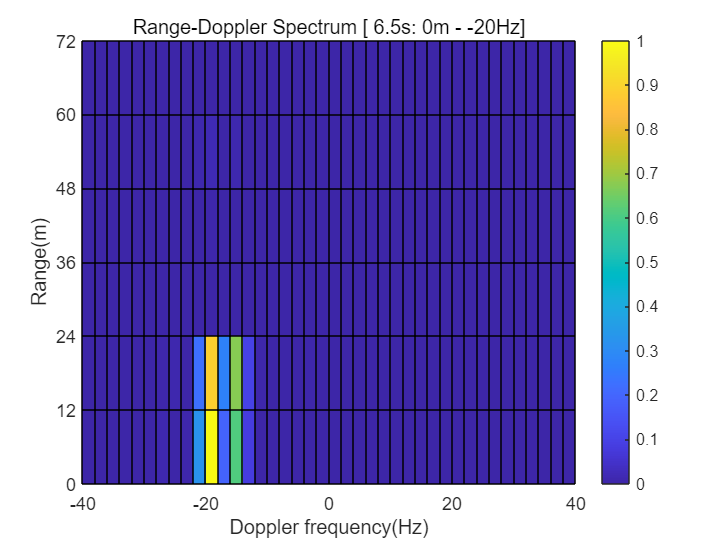

seq_ref1_after_LPF = 1.0e-03 *

  -0.0001 + 0.0000i  -0.0010 + 0.0002i  -0.0050 + 0.0011i  -0.0119 + 0.0041i  -0.0072 + 0.0100i   0.0319 + 0.0163i   0.0840 + 0.0158i   0.0731 + 0.0042i  -0.0035 - 0.0074i  -0.0187 + 0.0005i   0.0512 + 0.0225i   0.0416 + 0.0254i  -0.0529 + 0.0050i  -0.0397 - 0.0053i   0.0429 + 0.0051i   0.0156 + 0.0228i  -0.0598 + 0.0255i  -0.0714 - 0.0227i  -0.0270 - 0.0600i   0.0421 + 0.0367i  -0.0162 + 0.1556i  -0.1964 + 0.0993i  -0.1549 - 0.0045i   0.0615 - 0.0014i   0.0594 - 0.0221i  -0.0350 - 0.0888i   0.0168 - 0.0670i   0.0336 - 0.0100i  -0.0227 - 0.0037i  -0.0177 - 0.0087i   0.0158 - 0.0315i   0.0567 - 0.0874i   0.0582 - 0.1029i  -0.0366 - 0.0323i  -0.0988 + 0.0502i  -0.1033 + 0.0645i  -0.1338 + 0.0518i  -0.0599 + 0.0456i   0.1158 + 0.0147i   0.1093 + 0.0001i  -0.0592 + 0.0082i  -0.0902 - 0.0254i   0.0023 - 0.0465i   0.0117 - 0.0007i  -0.0483 + 0.0478i  -0.0783 + 0.0370i  -0.0455 - 0.0309i   0.0265 - 0.0516i   0.0263 - 0.0197i  -0.0339 - 0.0612i


seq_sur1_after_LPF =   -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0001 + 0.0001i  -0.0002 + 0.0004i  -0.0004 + 0.0007i  -0.0005 + 0.0008i  -0.0002 + 0.0004i   0.0004 + 0.0001i   0.0005 + 0.0000i   0.0001 + 0.0001i  -0.0002 + 0.0002i  -0.0002 + 0.0003i  -0.0003 + 0.0002i  -0.0005 - 0.0002i  -0.0000 - 0.0001i   0.0005 + 0.0002i   0.0001 - 0.0000i  -0.0005 - 0.0003i   0.0001 + 0.0000i   0.0007 + 0.0003i   0.0001 - 0.0001i  -0.0007 - 0.0006i  -0.0005 - 0.0003i   0.0000 + 0.0002i  -0.0001 - 0.0001i  -0.0002 - 0.0005i   0.0002 - 0.0001i   0.0003 + 0.0002i  -0.0003 + 0.0004i  -0.0002 + 0.0004i   0.0003 - 0.0000i   0.0003 + 0.0000i   0.0003 + 0.0004i   0.0003 + 0.0001i   0.0000 - 0.0004i  -0.0000 - 0.0003i  -0.0000 - 0.0004i  -0.0004 - 0.0002i  -0.0002 + 0.0005i   0.0004 + 0.0005i   0.0005 + 0.0000i   0.0002 + 0.0001i   0.0002 - 0.0002i   0.0002 - 0.0009i  -0.0001 - 0.0006i  -0.0002 + 0.0003i   0.0001 - 0.0000i   0.0001 - 0.0004i  -0.0001 + 0.0004i  -0.0002 + 0.0002i


matrix_normalized =     0.0001    0.0012    0.0002    0.0023    0.0002    0.0107    0.0078    0.0011    0.1165    0.0270    0.2812    1.0000    0.1978    0.0784    0.0042    0.0110    0.0328    0.0066    0.0052    0.0000    0.0000    0.0000    0.0011    0.0023    0.0001    0.0005    0.0002    0.0001    0.0007    0.0001    0.0001    0.0001    0.0003    0.0002    0.0002    0.0001    0.0001    0.0003    0.0000    0.0005    0.0004
    0.0017    0.0016    0.0020    0.0162    0.0001    0.0193    0.0159    0.0044    0.2909    0.0780    0.3142    0.9953    0.6807    0.1542    0.0014    0.0143    0.0930    0.0165    0.0058    0.0000    0.0000    0.0000    0.0004    0.0075    0.0001    0.0003    0.0000    0.0002    0.0009    0.0003    0.0016    0.0000    0.0002    0.0002    0.0005    0.0007    0.0000    0.0003    0.0000    0.0003    0.0000
    0.0000    0.0000    0.0000    0.0005    0.0005    0.0002    0.0001    0.0006    0.0037    0.0014    0.0003    0.0077    0.0006    0.0000    0.0004    0.00

cor_max_f_D = -18

cor_max_tau = 0

filename = 'Range-Doppler Spectrum data15.png'

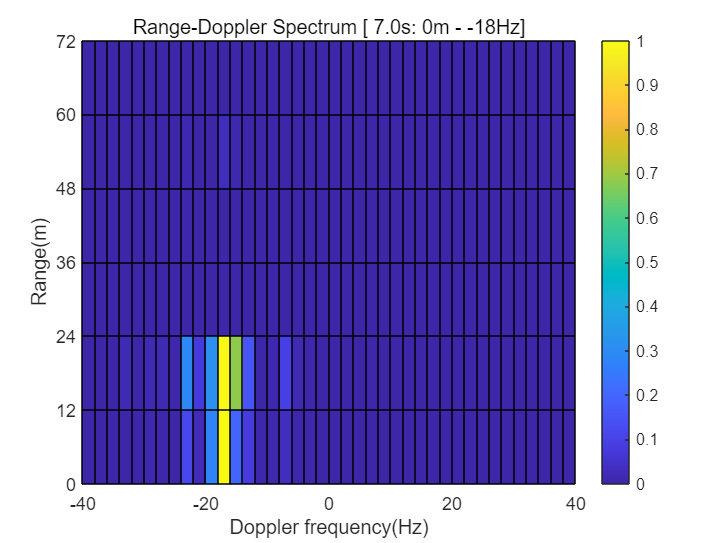

seq_ref1_after_LPF = 1.0e-03 *

  -0.0000 - 0.0000i  -0.0004 - 0.0002i  -0.0020 - 0.0004i  -0.0060 + 0.0011i  -0.0123 + 0.0100i  -0.0193 + 0.0292i  -0.0298 + 0.0462i  -0.0461 + 0.0405i  -0.0506 + 0.0215i  -0.0194 + 0.0198i   0.0231 + 0.0174i   0.0251 - 0.0262i   0.0053 - 0.0537i   0.0132 + 0.0110i   0.0077 + 0.0712i  -0.0379 + 0.0102i  -0.0242 - 0.0703i   0.0573 - 0.0562i   0.0632 - 0.0073i  -0.0065 + 0.0321i  -0.0324 + 0.0499i  -0.0268 - 0.0073i  -0.0161 - 0.0696i   0.0252 - 0.0383i   0.0221 + 0.0118i  -0.0399 + 0.0171i  -0.0347 - 0.0080i   0.0197 - 0.0483i   0.0220 - 0.0266i   0.0225 + 0.0199i   0.0407 - 0.0257i  -0.0030 - 0.0398i  -0.0483 + 0.0283i  -0.0018 + 0.0124i   0.0300 - 0.0167i  -0.0188 + 0.0213i  -0.0024 - 0.0078i   0.0878 - 0.0288i   0.0579 + 0.0465i  -0.0588 + 0.0611i  -0.0605 - 0.0005i   0.0037 - 0.0375i  -0.0098 - 0.0288i  -0.0406 + 0.0269i  -0.0292 + 0.0451i  -0.0307 + 0.0064i  -0.0288 + 0.0071i   0.0052 + 0.0137i   0.0068 + 0.0126i  -0.0263 + 0.0285i


seq_sur1_after_LPF =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0001 + 0.0000i   0.0002 + 0.0000i   0.0004 - 0.0001i   0.0004 - 0.0003i   0.0001 - 0.0003i  -0.0002 + 0.0002i  -0.0002 + 0.0005i  -0.0000 + 0.0002i   0.0000 + 0.0001i   0.0000 + 0.0002i   0.0000 - 0.0006i  -0.0002 - 0.0011i  -0.0004 - 0.0002i  -0.0001 + 0.0005i   0.0003 - 0.0002i   0.0000 - 0.0003i  -0.0009 + 0.0005i  -0.0009 + 0.0003i   0.0002 - 0.0001i   0.0006 - 0.0004i  -0.0002 - 0.0004i  -0.0007 - 0.0002i  -0.0003 - 0.0002i   0.0002 - 0.0003i   0.0002 + 0.0002i  -0.0003 + 0.0004i  -0.0005 + 0.0001i  -0.0001 + 0.0003i   0.0003 + 0.0006i   0.0002 + 0.0001i   0.0002 - 0.0002i   0.0002 - 0.0001i  -0.0001 + 0.0002i  -0.0004 + 0.0003i  -0.0002 - 0.0002i  -0.0001 - 0.0001i  -0.0003 + 0.0004i  -0.0003 + 0.0002i  -0.0001 - 0.0001i  -0.0001 - 0.0002i   0.0002 - 0.0002i   0.0006 + 0.0002i   0.0002 + 0.0004i  -0.0004 - 0.0001i   0.0001 - 0.0001i   0.0004 - 0.0001i  -0.0005 - 0.0003i  -0.0001 - 0.0001i


matrix_normalized =     0.0003    0.0001    0.0001    0.0015    0.0003    0.0001    0.0002    0.0087    0.0005    0.0090    0.0171    0.2846    0.0454    0.0066    0.0064    0.0019    0.0003    0.0064    0.0034         0    0.0000    0.0000    0.0006    0.0000    0.0008    0.0042    0.0005    0.0002    0.0005    0.0000    0.0001    0.0000    0.0020    0.0009    0.0004    0.0002    0.0002    0.0002    0.0001    0.0004    0.0016
    0.0040    0.0046    0.0000    0.0020    0.0009    0.0017    0.0005    0.0281    0.0073    0.0165    0.0236    1.0000    0.0809    0.0076    0.0164    0.0100    0.0001    0.0105    0.0238    0.0000    0.0000    0.0000    0.0067    0.0016    0.0008    0.0046    0.0039    0.0007    0.0025    0.0001    0.0021    0.0003    0.0041    0.0050    0.0001    0.0011    0.0001    0.0010    0.0009    0.0001    0.0055
    0.0013    0.0028    0.0000    0.0001    0.0002    0.0005    0.0006    0.0001    0.0007    0.0000    0.0000    0.0036    0.0017    0.0000    0.0000    0.00

cor_max_f_D = -18

cor_max_tau = 12

filename = 'Range-Doppler Spectrum data16.png'

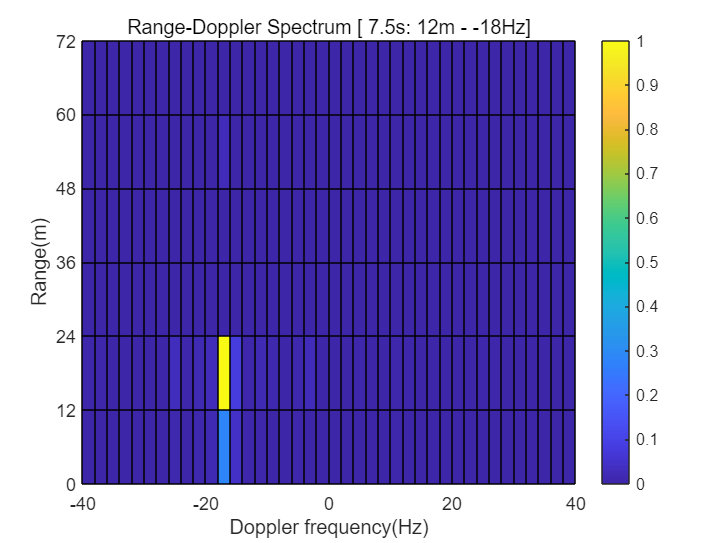

seq_ref1_after_LPF = 1.0e-03 *

  -0.0001 - 0.0000i  -0.0013 - 0.0005i  -0.0070 - 0.0024i  -0.0198 - 0.0082i  -0.0289 - 0.0216i  -0.0110 - 0.0450i   0.0262 - 0.0652i   0.0239 - 0.0500i  -0.0263 + 0.0011i  -0.0277 + 0.0263i   0.0431 - 0.0013i   0.0563 - 0.0207i  -0.0050 - 0.0174i  -0.0037 - 0.0339i   0.0470 - 0.0310i   0.0569 - 0.0014i   0.0768 - 0.0215i   0.0916 - 0.0283i   0.0327 + 0.0128i  -0.0050 - 0.0478i  -0.0104 - 0.1124i  -0.0519 + 0.0150i  -0.0205 + 0.0997i   0.0291 - 0.0147i  -0.0541 - 0.0752i  -0.0537 - 0.0448i   0.0580 - 0.0704i  -0.0412 - 0.0616i  -0.1733 + 0.0356i  -0.0381 + 0.0774i   0.0693 + 0.0137i   0.0006 - 0.0220i   0.0316 + 0.0249i   0.1217 + 0.0132i   0.0531 - 0.0659i  -0.0449 - 0.0581i  -0.0252 + 0.0216i  -0.0214 + 0.0761i  -0.0890 + 0.0507i  -0.0820 - 0.0354i   0.0110 - 0.0191i   0.0544 + 0.0686i   0.0042 + 0.0608i  -0.0665 + 0.0403i  -0.0310 + 0.0235i   0.1054 + 0.0011i   0.1587 + 0.1074i   0.1017 + 0.1349i   0.0460 - 0.0333i   0.0010 - 0.0616i


seq_sur1_after_LPF =   -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0001i   0.0000 + 0.0003i   0.0002 + 0.0005i   0.0003 + 0.0005i   0.0003 + 0.0001i   0.0000 - 0.0003i   0.0000 - 0.0003i   0.0002 + 0.0000i   0.0001 - 0.0001i   0.0002 - 0.0002i   0.0009 + 0.0002i   0.0012 + 0.0004i   0.0002 + 0.0001i  -0.0003 - 0.0001i   0.0002 + 0.0001i   0.0001 - 0.0001i  -0.0003 - 0.0008i   0.0001 - 0.0008i   0.0002 + 0.0003i   0.0002 + 0.0009i   0.0009 + 0.0004i   0.0009 + 0.0000i   0.0002 + 0.0002i  -0.0001 - 0.0000i  -0.0002 - 0.0003i   0.0001 - 0.0001i   0.0005 + 0.0002i  -0.0002 + 0.0001i  -0.0010 + 0.0002i  -0.0007 + 0.0003i  -0.0001 + 0.0002i   0.0003 + 0.0001i  -0.0000 + 0.0000i  -0.0005 - 0.0005i  -0.0000 - 0.0007i   0.0002 - 0.0002i  -0.0006 + 0.0003i  -0.0007 - 0.0000i  -0.0003 - 0.0003i   0.0001 + 0.0002i   0.0004 + 0.0005i  -0.0000 + 0.0003i  -0.0005 - 0.0000i   0.0002 - 0.0005i   0.0006 - 0.0006i   0.0002 - 0.0002i   0.0001 - 0.0005i  -0.0000 - 0.0003i


matrix_normalized = 7×41
    0.0004    0.0000    0.0000    0.0000    0.0002    0.0000    0.0005    0.0001    0.0014    0.0004    0.0155    0.0638    0.1126    0.0028    0.0029    0.0014    0.0014    0.0009    0.0016    0.0000    0.0000         0    0.0019    0.0000    0.0001    0.0002    0.0001    0.0000    0.0001    0.0002
    0.0001    0.0002    0.0000    0.0002    0.0000    0.0003    0.0058    0.0017    0.0168    0.0215    0.1486    0.8942    1.0000    0.0111    0.0110    0.0083    0.0015    0.0003    0.0000    0.0000    0.0000    0.0000    0.0009    0.0000    0.0000    0.0000    0.0007    0.0007    0.0002    0.0001
    0.0001    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0003    0.0007    0.0020    0.0016    0.0161    0.0200    0.0001    0.0001    0.0002    0.0001    0.0005    0.0010    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0000    0.0000    0.0001    0.0000    0.0004
    0.0001    0.0000    0.0000    0.0001    0.0000    0.0002    0.0004  

cor_max_f_D = -16

cor_max_tau = 12

filename = 'Range-Doppler Spectrum data17.png'

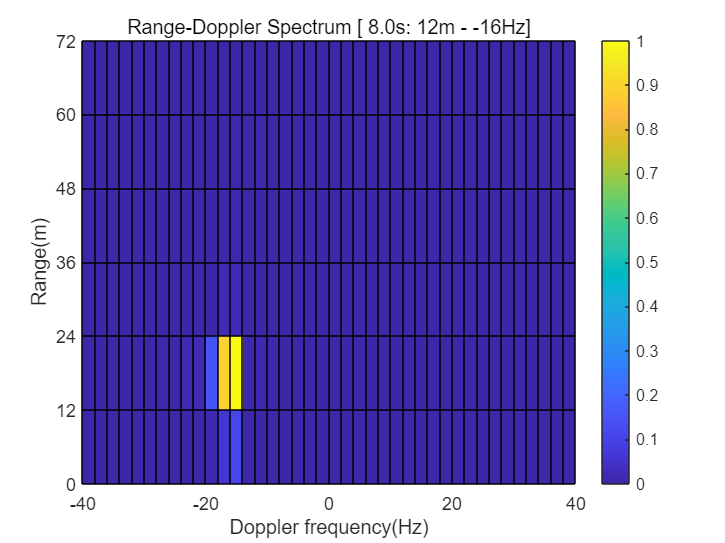

seq_ref1_after_LPF = 1×12500000
1.0e+00 *

  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0001i   0.0000 + 0.0001i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0001i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0001i  -0.0000 + 0.0001i  -0.0000 - 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0001i  -0.0001 - 0.0000i  -0.0001 - 0.0001i   0.0000 + 0.0001i   0.0001 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0001i   0.0000 - 0.0001i   0.0000 - 0.0002i  -0.0001 - 0.0001i


seq_sur1_after_LPF = 1×12500000
   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0001 - 0.0000i  -0.0004 - 0.0000i  -0.0006 + 0.0000i  -0.0005 + 0.0001i   0.0002 + 0.0002i   0.0005 + 0.0004i   0.0001 + 0.0004i  -0.0003 + 0.0002i  -0.0005 + 0.0003i  -0.0010 + 0.0008i  -0.0010 + 0.0009i   0.0002 + 0.0002i   0.0005 - 0.0001i  -0.0004 + 0.0001i  -0.0002 + 0.0000i   0.0007 + 0.0002i   0.0003 + 0.0005i  -0.0004 - 0.0001i  -0.0004 - 0.0003i  -0.0004 + 0.0008i  -0.0004 + 0.0008i  -0.0002 - 0.0002i  -0.0000 - 0.0001i   0.0003 + 0.0002i   0.0004 + 0.0001i   0.0001 + 0.0003i   0.0000 - 0.0001i


matrix_normalized = 7×41
    0.0068         0    0.0026    0.0285    0.0024    0.0017    0.0511    0.0028    0.0087    0.0112    0.0002    0.0457    0.0034    0.0005    0.0169    0.0000    0.0040    0.0422    0.0040    0.0007    0.0248    0.0030    0.0003    0.0082    0.0014    0.0112    0.0007    0.0022    0.0039    0.0075
    0.2866    0.0000    0.1639    0.2363    0.0434    0.0101    0.6256    0.0024    0.1461    0.0290    0.0484    0.3572    0.0361    0.2433    0.0089    0.0008    0.0806    1.0000    0.0493    0.0005    0.0204    0.0015    0.0007    0.4491    0.1713    0.0905    0.0175    0.0230    0.0091    0.1564
    0.0784    0.0003    0.0331    0.1059    0.0063    0.0037    0.1824    0.0002    0.0477    0.0014    0.0586    0.1124    0.0002    0.0141    0.0235    0.0004    0.0122    0.2814    0.0013    0.0000    0.0017    0.0000    0.0014    0.1073    0.0604    0.0180    0.0056    0.0161    0.0070    0.0170
    0.0070    0.0046    0.0108    0.0004    0.0002    0.0002    0.0030  

cor_max_f_D = -6

cor_max_tau = 12

filename = 'Range-Doppler Spectrum data18.png'

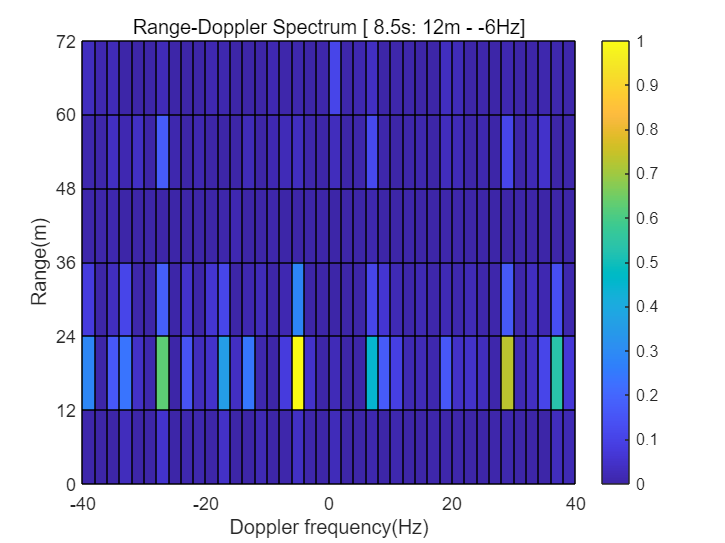

seq_ref1_after_LPF = 1×12500000
1.0e+00 *

  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0001i  -0.0000 + 0.0002i  -0.0001 + 0.0003i  -0.0001 + 0.0002i  -0.0001 - 0.0001i  -0.0000 - 0.0002i  -0.0001 + 0.0000i  -0.0001 + 0.0001i  -0.0000 - 0.0001i   0.0001 - 0.0002i   0.0001 - 0.0003i   0.0002 - 0.0003i   0.0003 + 0.0002i   0.0000 + 0.0005i  -0.0003 - 0.0001i   0.0001 - 0.0006i   0.0003 - 0.0000i  -0.0002 + 0.0003i  -0.0003 + 0.0001i  -0.0001 + 0.0001i  -0.0004 + 0.0002i  -0.0003 - 0.0004i  -0.0000 - 0.0005i  -0.0000 + 0.0001i   0.0001 + 0.0002i   0.0002 - 0.0002i  -0.0001 + 0.0000i  -0.0003 - 0.0001i


seq_sur1_after_LPF = 1×12500000
  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0001 - 0.0001i  -0.0002 - 0.0001i  -0.0002 - 0.0001i  -0.0001 + 0.0002i  -0.0003 + 0.0005i  -0.0014 + 0.0001i  -0.0020 - 0.0011i  -0.0010 - 0.0013i   0.0004 - 0.0002i   0.0003 + 0.0003i  -0.0004 - 0.0005i   0.0000 - 0.0003i   0.0002 + 0.0005i  -0.0009 - 0.0002i  -0.0011 - 0.0008i   0.0003 - 0.0003i   0.0003 - 0.0007i  -0.0012 + 0.0000i  -0.0006 + 0.0023i   0.0011 + 0.0014i   0.0009 - 0.0004i   0.0007 + 0.0004i   0.0012 - 0.0000i   0.0003 - 0.0007i   0.0003 + 0.0013i   0.0019 + 0.0012i   0.0020 - 0.0008i   0.0008 - 0.0002i


matrix_normalized = 7×41
    0.0094    0.0012    0.0007    0.0106    0.0117    0.0010    0.0412    0.0024    0.0271    0.0250    0.0062    0.0071    0.0118    0.0308    0.0463    0.1241    0.0734    0.6427    0.8886    0.0000    0.0005    0.0000    1.0000    0.6587    0.0642    0.0972    0.0491    0.0130    0.0106    0.0064
    0.0009    0.0006    0.0065    0.0000    0.0000    0.0001    0.0004    0.0003    0.0010    0.0014    0.0058    0.0001    0.0043    0.0112    0.0073    0.0039    0.0170    0.0360    0.2599    0.0000    0.0001    0.0000    0.3186    0.0599    0.0167    0.0033    0.0006    0.0019    0.0029    0.0004
    0.0000    0.0011    0.0006    0.0021    0.0001    0.0010    0.0013    0.0006    0.0066    0.0025    0.0004    0.0003    0.0001    0.0013    0.0006    0.0002    0.0002    0.0002    0.0008    0.0000    0.0000    0.0000    0.0084    0.0001    0.0001    0.0011    0.0002    0.0004    0.0001    0.0000
    0.0000    0.0000    0.0000    0.0013    0.0004    0.0014    0.0009  

cor_max_f_D = 4

cor_max_tau = 0

filename = 'Range-Doppler Spectrum data19.png'

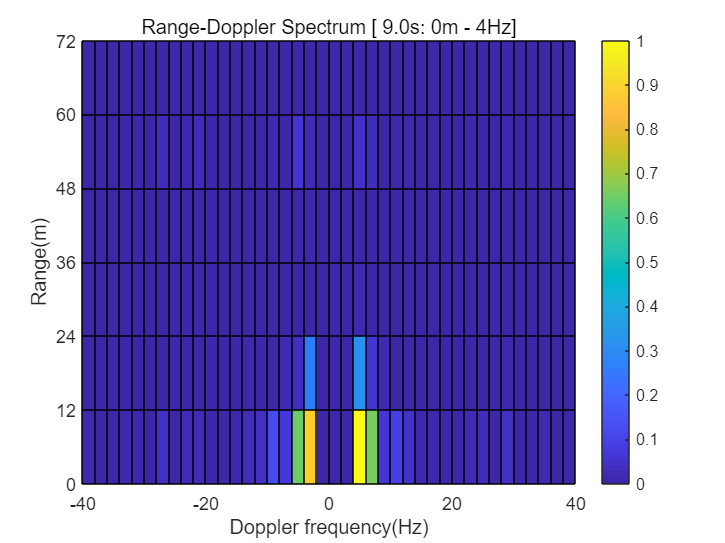

seq_ref1_after_LPF = 1×12500000
1.0e+00 *

  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0001i  -0.0001 - 0.0002i  -0.0002 - 0.0002i  -0.0002 + 0.0001i  -0.0000 + 0.0004i   0.0001 + 0.0002i  -0.0001 - 0.0002i  -0.0005 + 0.0002i  -0.0004 + 0.0008i   0.0003 + 0.0002i   0.0007 - 0.0007i   0.0000 - 0.0004i  -0.0006 + 0.0000i  -0.0004 - 0.0005i  -0.0002 - 0.0006i  -0.0005 + 0.0003i  -0.0002 + 0.0005i   0.0005 + 0.0002i   0.0007 + 0.0003i   0.0003 + 0.0001i  -0.0002 - 0.0002i  -0.0002 + 0.0001i   0.0001 + 0.0001i  -0.0003 + 0.0000i  -0.0007 + 0.0005i  -0.0003 + 0.0003i   0.0004 - 0.0001i   0.0002 + 0.0003i


seq_sur1_after_LPF = 1×12500000
   0.0000 - 0.0000i   0.0000 - 0.0001i   0.0000 - 0.0004i   0.0000 - 0.0010i  -0.0000 - 0.0013i  -0.0003 - 0.0007i  -0.0006 + 0.0003i  -0.0008 + 0.0000i  -0.0006 - 0.0011i  -0.0001 - 0.0007i  -0.0003 + 0.0004i  -0.0013 - 0.0002i  -0.0014 - 0.0015i   0.0001 - 0.0007i   0.0007 + 0.0009i  -0.0005 + 0.0015i  -0.0010 + 0.0013i  -0.0007 + 0.0006i  -0.0012 + 0.0003i  -0.0013 + 0.0012i  -0.0004 + 0.0020i   0.0001 + 0.0006i  -0.0001 - 0.0011i   0.0003 - 0.0003i   0.0014 + 0.0008i   0.0018 + 0.0001i   0.0006 - 0.0002i  -0.0002 + 0.0008i  -0.0000 + 0.0013i  -0.0006 + 0.0006i


matrix_normalized = 7×41
    0.0441    0.0050    0.0129    0.0254    0.0116    0.0076    0.0471    0.0235    0.0473    0.0070    0.0414    0.1307    0.0241    0.2830    0.0043    0.1066    0.0111    0.0004    0.0011    0.0034    0.0000    0.0021    0.0474    0.0117    0.1121    0.0389    0.1622    0.0014    0.0251    0.0563
    0.0045    0.0080    0.1370    0.0016    0.0858    0.0131    0.0655    0.0019    0.2263    0.0012    0.0354    0.0909    0.0000    0.0678    0.0487    0.1178    0.1490    0.0155    0.0015    0.0003    0.0000    0.0013    0.0038    0.0443    0.0053    0.0129    0.0089    0.0337    0.0117    0.0844
    0.0029    0.0029    0.6159    0.5100    0.0107    0.0399    0.0586    0.0025    0.0979    0.2087    0.0539    0.2760    0.0004    0.1228    0.0034    0.1188    0.0615    0.1348    0.0233    0.0000    0.0000    0.0002    0.0043    0.0021    0.0938    0.0331    0.1286    0.0022    0.0258    0.2328
    0.0696    0.0018    0.0131    0.3786    0.0199    0.0457    0.0041  

cor_max_f_D = 14

cor_max_tau = 48

filename = 'Range-Doppler Spectrum data20.png'

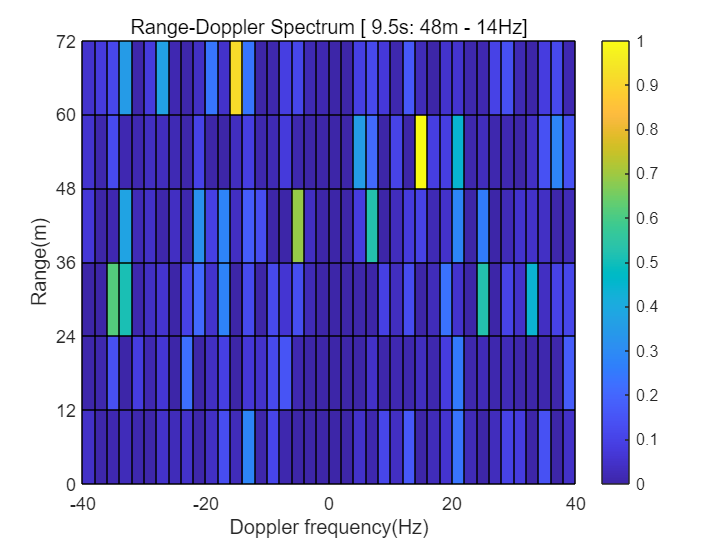

    seq_ref_after_LPF=AfterLPF_Timeseries(seq_ref,f_s);
    seq_sur_after_LPF=AfterLPF_Timeseries(seq_sur,f_s);
    ref_concatenated=[ref_concatenated,seq_ref1_after_LPF];
    sur_concatenated=[sur_concatenated,seq_ref1_after_LPF];
    
    %{
    cor_matrix=zeros([7,41]);
    N_tau=0:6;
    f_D=-40:2:40;
    for i=1:1:7
        for j=1:1:41
            seq_sur_cor=[seq_sur_after_LPF,zeros(1,N_tau(i))];
            seq_ref_cor=[zeros(1,N_tau(i)),seq_ref_after_LPF];
            n_spaced=0:length(seq_sur_cor)-1;
            cor_matrix(i,j)=abs(sum(seq_sur_cor.*conj(seq_ref_cor).*exp((-2i*pi*f_D(j)/f_s)*n_spaced)));
        end
    end

    minVal = min(cor_matrix(:));
    maxVal = max(cor_matrix(:));
    
    % 进行 0-1 标准化,3次方加强效果
    matrix_normalized = ((cor_matrix - minVal) / (maxVal - minVal)).^3

    % 使用max函数找到矩阵中的最大元素及其位置
    [maxValue, linearIndex] = max(matrix_normalized(:));
    % 将线性索引转换为行列索引
    [row, col] = ind2sub(size(matrix_normalized), linearIndex);
    cor_max_f_D=(col-1)*2-40
    cor_max_tau=(row-1)*3e8/f_s

    figure
    pcolor(f_D,N_tau*3e8/f_s,matrix_normalized)
    colorbar;
    xlabel("Doppler frequency(Hz)"),ylabel("Range(m)"),yticks([0,12,24,36,48,60,72]);
    Title = sprintf('Range-Doppler Spectrum [%4.1fs: %dm - %dHz]', 0.5*data_index-0.5, cor_max_tau, cor_max_f_D);
    title(Title)

    % 保存图形
    filename = sprintf('Range-Doppler Spectrum data%d.png', data_index)
    saveas(gcf, filename);
    %}

end 

Task3

Time=[];
Doppler_frequency=[];
Time_Doppler_matrix=[];
sliding_window_len=0.1*f_s
num_windows=length(ref_concatenated)/sliding_window_len
for window_index=1:num_windows

    time=0.1*(window_index-1);
    Time=[Time,time];

    ref_segment=ref_concatenated((window_index:window_index+1)*sliding_window_len);
    sur_segment=sur_concatenated((window_index:window_index+1)*sliding_window_len);
    
    cor_matrix=zeros([7,41]);
    N_tau=0:6;
    f_D=-40:2:40;
    for i=1:1:7
        for j=1:1:41
            seq_sur_cor=[ref_segment,zeros(1,N_tau(i))];
            seq_ref_cor=[zeros(1,N_tau(i)),sur_segment];
            n_spaced=0:length(seq_sur_cor)-1;
            cor_matrix(i,j)=abs(sum(seq_sur_cor.*conj(seq_ref_cor).*exp((-2i*pi*f_D(j)/f_s)*n_spaced)));
    [maxValue, linearIndex] = max(cor_matrix(:));
    % 将线性索引转换为行列索引
    [row, col] = ind2sub(size(matrix_normalized), linearIndex);
    Time_Doppler_matrix=[Time_Doppler_matrix;cor_matrix(row)];
        end
    end
end

figure
pcolor(Doppler_frequency,Time,Time_Doppler_matrix)
colorbar;
xlabel("Doppler frequency(Hz)"),ylabel("Range(m)"),yticks([0,12,24,36,48,60,72]);
Title = sprintf('Range-Doppler Spectrum [%4.1fs: %dm - %dHz]', 0.5*data_index-0.5, cor_max_tau, cor_max_f_D);
title(Title)

% 保存图形
filename = sprintf('Range-Doppler Spectrum data%d.png', data_index)
saveas(gcf, filename);

function drawSpectrum(x,fs)
    N=length(x);
    H=fftshift(fft(x));
    f=(-N/2:N/2-1)*fs/N;
    figure,set(gcf, 'Position', [100 100 1000 800])
    subplot(3,2,1),plot(f./10^6,20*log10(abs(H)))
    xlabel("Frequency(MHz)"),ylabel('Amplitude(dB)'),ylim([-80,0])
    title('Spectrum (raw)')
end

function [H,H_filtered]=SpectrumExtraction(x,fs)
    f_ddc=-3e6;
    bandwidth=9e6;
    x=x.*exp(-1j*2*pi*f_ddc*xTime(x,fs));

    %DDC
    H=fftshift(fft(x));
    
    %LPF
    [b,a]=butter(20,bandwidth/(fs/2),'low');
    x_filtered=filter(b,a,x);
    H_filtered=fftshift(fft(x_filtered));
end

function drawDDCSpectrum(x,fs)
    [H,~]=SpectrumExtraction(x,fs);

    N=length(x);
    f=(-N/2:N/2-1)*fs/N;
    subplot(3,2,3),plot(f./10^6,20*log10(abs(H)))
    xlabel("Frequency(MHz)"),ylabel('Amplitude(dB)'),ylim([-80,0])
    title('Spectrum (after DDC)')
end

function AfterLPFSpectrum(x,fs)
    [~,H]=SpectrumExtraction(x,fs);

    N=length(x);
    f=(-N/2:N/2-1)*fs/N;
    subplot(3,2,5),plot(f./10^6,20*log10(abs(H)))
    ylabel('Amplitude(dB)'),ylim([-70,0]),xlabel('Frequency(MHz)')
    title('Spectrum (after LPF)')
end

function t=xTime(x,fs)
    t=(0:length(x)-1)./fs;%将x轴用时间表示
end

function TimePlotting(x,fs,Title)
    t=xTime(x,fs);
    subplot(3,2,2),ylim([-4*1e3,4*1e3]),plot(t*1e3,x)
    ylabel("Amplitude"),xlabel("Time(ms)"),ylim([-4*1e-3,4*1e-3])
    title(Title)
end

function DDC_TimePlotting(x,fs,Title)
    f_ddc=-3e6;

    t=xTime(x,fs);
    x=x.*exp(-1j*2*pi*f_ddc*xTime(x,fs));
    subplot(3,2,4),plot(t*1e3,x)
    ylabel("Amplitude"),xlabel("Time(ms)"),ylim([-4*1e-3,4*1e-3]),title(Title)
end

function AfterLPF_TimePlotting(x,fs,Title,Filename,data_index)
    f_ddc=-3e6;
    bandwidth=9e6;
    t=xTime(x,fs);

    x=x.*exp(-1j*2*pi*f_ddc*xTime(x,fs));
    [b,a]=butter(20,bandwidth/(fs/2),'low');
    x_filtered=filter(b,a,x);
    subplot(3,2,6),plot(t*1e3,x_filtered);
    ylabel("Amplitude"),xlabel("Time(ms)"),ylim([-4*1e-3,4*1e-3]),title(Title)

    filename=sprintf('%s data%d.png', Filename, data_index);
    saveas(gcf, filename);
end

function x_filtered=AfterLPF_Timeseries(x,fs)
    f_ddc=-3e6;
    bandwidth=9e6;
    t=xTime(x,fs);

    x=x.*exp(-1j*2*pi*f_ddc*xTime(x,fs));
    [b,a]=butter(20,bandwidth/(fs/2),'low');
    x_filtered=filter(b,a,x);
end

%{
function Cor=cor(tau,f_D,y_surv,y_ref,fs)
    zero_compensation =zeros([1,fix(tau*fs)]);
    y_surv_com=[y_surv,zero_compensation];
    y_ref_com=[zero_compensation,y_ref];
    function y=exp_component(n,f_D,fs)
        y=exp((-2i*pi*f_D/fs)*linspace(0,n-1,n));
    end
    Cor=abs(sum(y_surv_com.*conj(y_ref_com).*exp_component(length(y_surv_com),f_D,fs)));
end
%}